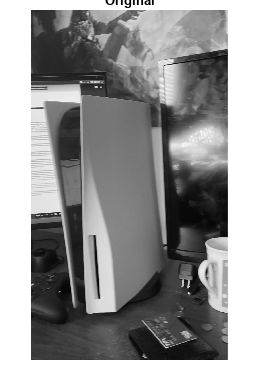

clear all;
close all;
%Question 1

% Getting video and selecting frame to be used
vid = VideoReader('assignent3.mp4');
vid.CurrentTime = 6;
vidFrame = vid.readFrame();

%Presenting the frames%
figure;
grayImage = rgb2gray(vidFrame);
imshow(grayImage);
title('Original');


%Cropping image
Icropped = imcrop(grayImage);
imshow(Icropped);
title('Cropped Image');

%Adding random image frames to be compared
vid.CurrentTime = 0;
vidFrame0 = vid.readFrame();
grayImage0 = rgb2gray(vidFrame0);

vid.CurrentTime = 1;
vidFrame1 = vid.readFrame();
grayImage1 = rgb2gray(vidFrame1);

vid.CurrentTime = 2;
vidFrame2 = vid.readFrame();
grayImage2 = rgb2gray(vidFrame2);

vid.CurrentTime = 3;
vidFrame3 = vid.readFrame();
grayImage3 = rgb2gray(vidFrame3);

vid.CurrentTime = 4;
vidFrame4 = vid.readFrame();
grayImage4 = rgb2gray(vidFrame4);

vid.CurrentTime = 5;
vidFrame5 = vid.readFrame();
grayImage5 = rgb2gray(vidFrame5);

vid.CurrentTime = 5.5;
vidFrame6 = vid.readFrame();
grayImage6 = rgb2gray(vidFrame6);

vid.CurrentTime = 6.2;
vidFrame7 = vid.readFrame();
grayImage7 = rgb2gray(vidFrame7);

vid.CurrentTime = 6.5;
vidFrame8 = vid.readFrame();
grayImage8 = rgb2gray(vidFrame8);

vid.CurrentTime = 6.8;
vidFrame9 = vid.readFrame();
grayImage9 = rgb2gray(vidFrame9);


%Comparing Images to our cropped image and drawing regions

%Comparing Image 1
montage({Icropped,grayImage0});

c = normxcorr2(Icropped,grayImage0)
surf(c)
shading flat
[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(Icropped,1);
xoffSet = xpeak-size(Icropped,2);
imshow(grayImage0)
drawrectangle(gca,'Position',[xoffSet,yoffSet,size(Icropped,2),size(Icropped,1)], ...
    'FaceAlpha',0);

%Comparing Image 2
montage({Icropped,grayImage1});

c = normxcorr2(Icropped,grayImage1)
surf(c)
shading flat
[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(Icropped,1);
xoffSet = xpeak-size(Icropped,2);
imshow(grayImage1)
drawrectangle(gca,'Position',[xoffSet,yoffSet,size(Icropped,2),size(Icropped,1)], ...
    'FaceAlpha',0);

%Comparing Image 3
montage({Icropped,grayImage2});

c = normxcorr2(Icropped,grayImage2)
surf(c)
shading flat
[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(Icropped,1);
xoffSet = xpeak-size(Icropped,2);
imshow(grayImage2)
drawrectangle(gca,'Position',[xoffSet,yoffSet,size(Icropped,2),size(Icropped,1)], ...
    'FaceAlpha',0);

%Comparing Image 4
montage({Icropped,grayImage3});

c = normxcorr2(Icropped,grayImage3)
surf(c)
shading flat
[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(Icropped,1);
xoffSet = xpeak-size(Icropped,2);
imshow(grayImage3)
drawrectangle(gca,'Position',[xoffSet,yoffSet,size(Icropped,2),size(Icropped,1)], ...
    'FaceAlpha',0);

%Comparing Image 5
montage({Icropped,grayImage4});

c = normxcorr2(Icropped,grayImage4)
surf(c)
shading flat
[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(Icropped,1);
xoffSet = xpeak-size(Icropped,2);
imshow(grayImage4)
drawrectangle(gca,'Position',[xoffSet,yoffSet,size(Icropped,2),size(Icropped,1)], ...
    'FaceAlpha',0);

%Comparing Image 6
montage({Icropped,grayImage5});

c = normxcorr2(Icropped,grayImage5)
surf(c)
shading flat
[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(Icropped,1);
xoffSet = xpeak-size(Icropped,2);
imshow(grayImage5)
drawrectangle(gca,'Position',[xoffSet,yoffSet,size(Icropped,2),size(Icropped,1)], ...
    'FaceAlpha',0);

%Comparing Image 7
montage({Icropped,grayImage6});

c = normxcorr2(Icropped,grayImage6)
surf(c)
shading flat
[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(Icropped,1);
xoffSet = xpeak-size(Icropped,2);
imshow(grayImage6)
drawrectangle(gca,'Position',[xoffSet,yoffSet,size(Icropped,2),size(Icropped,1)], ...
    'FaceAlpha',0);

%Comparing Image 8
montage({Icropped,grayImage7});

c = normxcorr2(Icropped,grayImage7)
surf(c)
shading flat
[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(Icropped,1);
xoffSet = xpeak-size(Icropped,2);
imshow(grayImage7)
drawrectangle(gca,'Position',[xoffSet,yoffSet,size(Icropped,2),size(Icropped,1)], ...
    'FaceAlpha',0);

%Comparing Image 9
montage({Icropped,grayImage8});

c = normxcorr2(Icropped,grayImage8)
surf(c)
shading flat
[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(Icropped,1);
xoffSet = xpeak-size(Icropped,2);
imshow(grayImage8)
drawrectangle(gca,'Position',[xoffSet,yoffSet,size(Icropped,2),size(Icropped,1)], ...
    'FaceAlpha',0);

%Comparing Image 10
montage({Icropped,grayImage9});

c = normxcorr2(Icropped,grayImage9)
surf(c)
shading flat
[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(Icropped,1);
xoffSet = xpeak-size(Icropped,2);
imshow(grayImage9)
drawrectangle(gca,'Position',[xoffSet,yoffSet,size(Icropped,2),size(Icropped,1)], ...
    'FaceAlpha',0);

%Question 2 can be found in the "Question 2" folder

%Question 3
vidReader = VideoReader('assignent3.mp4','CurrentTime', 5);
opticFlow = opticalFlowHS;

h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = im2gray(frameRGB);  
    flow = estimateFlow(opticFlow,frameGray);
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',60,'Parent',hPlot);
    hold off
    pause(10^-3)
end

%Question 4
% Getting video and selecting frame to be used
vid = VideoReader('assignent3.mp4');
vid.CurrentTime = 9;
vidFrame_1 = vid.readFrame();

subplot(1,3,1)
imshow(vidFrame_1)

%thresholding
% Convert RGB image to chosen color space
I = rgb2hsv(vidFrame_1);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.244;
channel1Max = 0.461;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.211;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.830;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

subplot(1,3,2)
imshow(BW)

%remove noise
rectangleElem = strel('rectangle',[2,3]);
Ibwopen = imopen(BW,rectangleElem);
subplot(1,3,3)
imshow(Ibwopen)


%annotate image
Ishape = insertShape(vidFrame_1, 'rectangle',bboxOut, 'Linewidth' ,10);
figure;
subplot(1,2,1);
imshow(Ishape);

%Shape not showing correctly?

%IMAGE 2
vid.CurrentTime = 9.5;
vidFrame_2 = vid.readFrame();

subplot(1,3,1)
imshow(vidFrame_2)

%thresholding
% Convert RGB image to chosen color space
I = rgb2hsv(vidFrame_2);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.244;
channel1Max = 0.461;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.211;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.830;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

subplot(1,3,2)
imshow(BW)

%remove noise
rectangleElem = strel('rectangle',[2,3]);
Ibwopen = imopen(BW,rectangleElem);
subplot(1,3,3)
imshow(Ibwopen)


%annotate image
Ishape = insertShape(vidFrame_2, 'rectangle',bboxOut, 'Linewidth' ,10);
figure;
subplot(1,2,1);
imshow(Ishape);

%Question 5
clear all;

cam = webcam();
cam.Resolution = '640x480';
video_Frame = snapshot(cam);

video_Player = vision.VideoPlayer('Position', [100 100 432 240]);

face_Detector = vision.CascadeObjectDetector();
point_Tracker = vision.PointTracker('MaxBidirectionalError', 2);

run_loop = true;
number_of_Points = 0;
frame_Count = 0;

while run_loop && frame_Count <400

    video_Frame = snapshot(cam);
    gray_Frame = rgb2gray(video_Frame);
    frame_Count = frame_Count+1;

    if number_of_Points < 10
        face_Rectangle = face_Detector.step(gray_Frame);

        if ~isempty(face_Rectangle)
            points = detectMinEigenFeatures(gray_Frame, 'ROI', face_Rectangle(1, :));

            xy_Points = points.Location;
            number_of_Points = size(xy_Points, 1);
            release(point_Tracker);
            initialize(point_Tracker, xy_Points, gray_Frame);

            previous_Points = xy_Points;

            rectangle = bbox2points(face_Rectangle(1, :));
            face_Polygon = reshape(rectangle',1, []);

            video_Frame = insertShape(video_Frame, 'Polygon', face_Polygon, 'LineWidth', 3);
            video_Frame = insertMarker(video_Frame, xy_Points, '+', 'Color', 'white');
        end
    else
        [xy_Points, isFound] = step(point_Tracker, gray_Frame);
        new_Points = xy_Points(isFound, :);
        old_Points = previous_Points(isFound, :);

        number_of_Points = size(new_Points,1);

        if number_of_Points >= 10
            [xform, old_Points, new_Points] = estimateGeometricTransform(...
                old_Points, new_Points, 'similarity', 'MaxDistance', 4)

            rectangle = transformPointsForward(xform, rectangle);

            face_Polygon = reshape(rectangle', 1, []);

            video_Frame = insertShape(video_Frame, 'Polygon', face_Polygon, 'LineWidth', 3);
            video_Frame = insertMarker(video_Frame, new_Points, '+', 'Color', 'white');

            previous_Points = new_Points;
            setPoints(point_Tracker, previous_Points);
        end
    end
    step(video_Player, video_Frame);
    run_loop = isOpen(video_Player);
end

xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  453.3490  124.7687
  453.1539  130.9681
  452.7919  134.9408
  453.0000  161.0000
  453.3078  177.7074
  453.1696  184.4610
  453.5955  140.7911
  454.2647  154.1390
  453.8162  189.6513
  454.4053  156.9454


new_Points = 100×2 single matrix
  452.4509  123.6394
  452.3057  131.3530
  452.0631  134.5401
  452.2503  160.2690
  453.3554  178.9684
  453.1457  184.8562
  452.9326  140.2012
  453.6529  153.9569
  453.8628  189.2054
  453.8251  156.8308


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  452.4509  123.6394
  452.3057  131.3530
  452.0631  134.5401
  452.2503  160.2690
  453.3554  178.9684
  453.1457  184.8562
  452.9326  140.2012
  453.6529  153.9569
  453.8628  189.2054
  453.8251  156.8308


new_Points = 100×2 single matrix
  452.3681  123.7181
  452.2419  131.3566
  452.0218  134.5548
  452.2518  160.1457
  453.4883  178.9744
  453.2624  184.5420
  452.8903  140.1401
  453.6496  153.9964
  453.9935  188.9307
  453.8246  156.8555


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  452.3681  123.7181
  452.2419  131.3566
  452.0218  134.5548
  452.2518  160.1457
  453.4883  178.9744
  453.2624  184.5420
  452.8903  140.1401
  453.6496  153.9964
  453.9935  188.9307
  453.8246  156.8555


new_Points = 100×2 single matrix
  452.2609  123.5543
  452.1619  131.3553
  451.9444  134.5772
  452.4200  160.1220
  453.6996  178.7803
  453.4336  184.2127
  452.8950  140.2515
  453.7437  153.9665
  454.1986  188.9940
  453.9797  156.7968


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  452.2609  123.5543
  452.1619  131.3553
  451.9444  134.5772
  452.4200  160.1220
  453.6996  178.7803
  453.4336  184.2127
  452.8950  140.2515
  453.7437  153.9665
  454.1986  188.9940
  453.9797  156.7968


new_Points = 100×2 single matrix
  452.1328  123.6510
  452.0397  131.1436
  451.8187  134.4123
  452.2572  159.8315
  453.6541  178.6399
  453.4037  184.1954
  452.7383  140.0271
  453.5787  153.6927
  454.1293  188.7401
  453.8109  156.5744


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  452.1328  123.6510
  452.0397  131.1436
  451.8187  134.4123
  452.2572  159.8315
  453.6541  178.6399
  453.4037  184.1954
  452.7383  140.0271
  453.5787  153.6927
  454.1293  188.7401
  453.8109  156.5744


new_Points = 100×2 single matrix
  451.9297  123.4596
  451.8447  131.0554
  451.6375  134.2091
  452.0164  159.6163
  453.4898  178.5349
  453.1875  183.8507
  452.5612  139.8463
  453.4176  153.5983
  453.9049  188.3884
  453.6235  156.4611


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  451.9297  123.4596
  451.8447  131.0554
  451.6375  134.2091
  452.0164  159.6163
  453.4898  178.5349
  453.1875  183.8507
  452.5612  139.8463
  453.4176  153.5983
  453.9049  188.3884
  453.6235  156.4611


new_Points = 100×2 single matrix
  451.5231  123.4662
  451.4371  131.2552
  451.2516  134.3175
  451.7160  159.6688
  453.1932  178.5487
  452.8815  183.9488
  452.1749  139.9918
  453.0534  153.5628
  453.5590  188.2445
  453.3243  156.4380


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  451.5231  123.4662
  451.4371  131.2552
  451.2516  134.3175
  451.7160  159.6688
  453.1932  178.5487
  452.8815  183.9488
  452.1749  139.9918
  453.0534  153.5628
  453.5590  188.2445
  453.3243  156.4380


new_Points = 100×2 single matrix
  450.9574  123.3020
  450.8894  131.2267
  450.6903  134.3077
  451.2809  159.6261
  452.9775  179.0413
  452.6274  184.2942
  451.6328  139.8322
  452.5820  153.5851
  453.2686  188.2794
  452.8594  156.4639


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  450.9574  123.3020
  450.8894  131.2267
  450.6903  134.3077
  451.2809  159.6261
  452.9775  179.0413
  452.6274  184.2942
  451.6328  139.8322
  452.5820  153.5851
  453.2686  188.2794
  452.8594  156.4639


new_Points = 100×2 single matrix
  450.2846  123.4710
  450.2401  131.3691
  450.0480  134.5051
  450.6500  159.8025
  452.3860  179.2736
  452.0885  184.5217
  451.0205  140.0852
  451.9932  153.7974
  452.7494  188.3225
  452.2567  156.6704


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  450.2846  123.4710
  450.2401  131.3691
  450.0480  134.5051
  450.6500  159.8025
  452.3860  179.2736
  452.0885  184.5217
  451.0205  140.0852
  451.9932  153.7974
  452.7494  188.3225
  452.2567  156.6704


new_Points = 100×2 single matrix
  450.1091  123.4140
  450.0713  131.7039
  449.8985  134.7696
  450.4987  160.0274
  452.3500  179.7900
  452.0749  185.2397
  450.8722  140.3186
  451.8713  154.0677
  452.6892  188.6944
  452.1283  156.9579


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  450.1091  123.4140
  450.0713  131.7039
  449.8985  134.7696
  450.4987  160.0274
  452.3500  179.7900
  452.0749  185.2397
  450.8722  140.3186
  451.8713  154.0677
  452.6892  188.6944
  452.1283  156.9579


new_Points = 100×2 single matrix
  450.0086  123.4637
  449.9647  131.9624
  449.8114  135.0258
  450.5439  160.0987
  452.3988  179.8624
  452.1124  185.2285
  450.8001  140.4265
  451.8755  154.1337
  452.7034  188.6756
  452.1724  157.0037


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  450.0086  123.4637
  449.9647  131.9624
  449.8114  135.0258
  450.5439  160.0987
  452.3988  179.8624
  452.1124  185.2285
  450.8001  140.4265
  451.8755  154.1337
  452.7034  188.6756
  452.1724  157.0037


new_Points = 100×2 single matrix
  449.9658  123.3338
  449.9312  132.0039
  449.7752  135.0729
  450.4427  160.1603
  452.3946  179.9809
  452.1563  185.3775
  450.7401  140.4684
  451.8014  154.2052
  452.7674  188.7300
  452.0766  157.0796


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  449.9658  123.3338
  449.9312  132.0039
  449.7752  135.0729
  450.4427  160.1603
  452.3946  179.9809
  452.1563  185.3775
  450.7401  140.4684
  451.8014  154.2052
  452.7674  188.7300
  452.0766  157.0796


new_Points = 100×2 single matrix
  449.9646  123.4149
  449.9299  132.0173
  449.7780  135.0700
  450.5558  160.3883
  452.4543  180.1537
  452.2112  185.4815
  450.7979  140.5866
  451.8885  154.4035
  452.8166  188.8404
  452.1809  157.2641


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  449.9646  123.4149
  449.9299  132.0173
  449.7780  135.0700
  450.5558  160.3883
  452.4543  180.1537
  452.2112  185.4815
  450.7979  140.5866
  451.8885  154.4035
  452.8166  188.8404
  452.1809  157.2641


new_Points = 100×2 single matrix
  450.1857  123.5151
  450.1504  132.3238
  450.0102  135.3627
  450.8386  160.4754
  452.6832  180.2587
  452.4359  185.6508
  451.0106  140.8430
  452.2076  154.5446
  453.0709  188.9852
  452.4781  157.3990


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  450.1857  123.5151
  450.1504  132.3238
  450.0102  135.3627
  450.8386  160.4754
  452.6832  180.2587
  452.4359  185.6508
  451.0106  140.8430
  452.2076  154.5446
  453.0709  188.9852
  452.4781  157.3990


new_Points = 100×2 single matrix
  450.5084  123.3996
  450.4402  132.2201
  450.2913  135.1382
  451.0046  160.3175
  452.8589  180.0995
  452.6158  185.5161
  451.2809  140.6789
  452.4145  154.4175
  453.2676  188.9039
  452.6616  157.2593


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  450.5084  123.3996
  450.4402  132.2201
  450.2913  135.1382
  451.0046  160.3175
  452.8589  180.0995
  452.6158  185.5161
  451.2809  140.6789
  452.4145  154.4175
  453.2676  188.9039
  452.6616  157.2593


new_Points = 100×2 single matrix
  450.7848  123.4077
  450.7260  132.2405
  450.5772  135.1492
  451.2908  160.3589
  453.1888  180.2435
  452.9023  185.5232
  451.5876  140.6541
  452.6581  154.4500
  453.5607  188.9717
  452.9411  157.3040


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  450.7848  123.4077
  450.7260  132.2405
  450.5772  135.1492
  451.2908  160.3589
  453.1888  180.2435
  452.9023  185.5232
  451.5876  140.6541
  452.6581  154.4500
  453.5607  188.9717
  452.9411  157.3040


new_Points = 100×2 single matrix
  451.1816  123.5688
  451.1272  132.3258
  450.9694  135.2600
  451.6723  160.4676
  453.5409  180.4489
  453.3739  186.1119
  451.9851  140.6692
  453.0848  154.5044
  453.9785  189.2649
  453.3388  157.3727


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  451.1816  123.5688
  451.1272  132.3258
  450.9694  135.2600
  451.6723  160.4676
  453.5409  180.4489
  453.3739  186.1119
  451.9851  140.6692
  453.0848  154.5044
  453.9785  189.2649
  453.3388  157.3727


new_Points = 100×2 single matrix
  450.9648  123.2428
  450.9225  131.9828
  450.7881  134.9895
  451.4605  160.1007
  453.3777  180.1842
  453.1888  185.7200
  451.8098  140.3710
  452.8803  154.1803
  453.8305  189.0646
  453.1252  157.0139


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  450.9648  123.2428
  450.9225  131.9828
  450.7881  134.9895
  451.4605  160.1007
  453.3777  180.1842
  453.1888  185.7200
  451.8098  140.3710
  452.8803  154.1803
  453.8305  189.0646
  453.1252  157.0139


new_Points = 100×2 single matrix
  450.5404  123.3529
  450.5265  132.0323
  450.4070  135.0249
  451.0942  160.1491
  453.0703  180.2683
  452.9083  185.8940
  451.4083  140.3812
  452.5244  154.1923
  453.5638  189.1536
  452.7570  157.0368


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  450.5404  123.3529
  450.5265  132.0323
  450.4070  135.0249
  451.0942  160.1491
  453.0703  180.2683
  452.9083  185.8940
  451.4083  140.3812
  452.5244  154.1923
  453.5638  189.1536
  452.7570  157.0368


new_Points = 100×2 single matrix
  450.2570  123.4684
  450.2647  132.0307
  450.1458  135.1523
  450.8035  160.2930
  452.7481  180.3367
  452.5872  185.9483
  451.1501  140.4892
  452.2361  154.2656
  453.2668  189.3434
  452.4617  157.1317


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  450.2570  123.4684
  450.2647  132.0307
  450.1458  135.1523
  450.8035  160.2930
  452.7481  180.3367
  452.5872  185.9483
  451.1501  140.4892
  452.2361  154.2656
  453.2668  189.3434
  452.4617  157.1317


new_Points = 100×2 single matrix
  449.7923  123.3738
  449.7925  132.0263
  449.6622  135.0731
  450.4032  160.1000
  452.4229  180.3353
  452.2675  185.9018
  450.6836  140.3590
  451.8115  154.1408
  452.9096  189.2518
  452.0601  156.9722


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  449.7923  123.3738
  449.7925  132.0263
  449.6622  135.0731
  450.4032  160.1000
  452.4229  180.3353
  452.2675  185.9018
  450.6836  140.3590
  451.8115  154.1408
  452.9096  189.2518
  452.0601  156.9722


new_Points = 100×2 single matrix
  449.2495  123.2539
  449.2384  131.9783
  449.1047  134.9651
  449.9266  159.9113
  451.8896  180.0438
  451.7598  185.7938
  450.1385  140.3006
  451.3607  153.9939
  452.4582  189.2662
  451.6086  156.8307


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  449.2495  123.2539
  449.2384  131.9783
  449.1047  134.9651
  449.9266  159.9113
  451.8896  180.0438
  451.7598  185.7938
  450.1385  140.3006
  451.3607  153.9939
  452.4582  189.2662
  451.6086  156.8307


new_Points = 100×2 single matrix
  448.4592  123.2816
  448.4640  132.0168
  448.3482  135.0463
  449.2497  159.9678
  451.3496  180.3624
  451.2129  185.9144
  449.4409  140.3106
  450.6786  154.0573
  451.9055  189.3013
  450.9245  156.9095


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  448.4592  123.2816
  448.4640  132.0168
  448.3482  135.0463
  449.2497  159.9678
  451.3496  180.3624
  451.2129  185.9144
  449.4409  140.3106
  450.6786  154.0573
  451.9055  189.3013
  450.9245  156.9095


new_Points = 100×2 single matrix
  447.7449  123.3826
  447.7793  132.1631
  447.6539  135.1790
  448.6530  160.2559
  450.9039  180.8797
  450.7748  186.3547
  448.7480  140.4475
  450.0935  154.3026
  451.4968  189.6385
  450.3354  157.1602


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  447.7449  123.3826
  447.7793  132.1631
  447.6539  135.1790
  448.6530  160.2559
  450.9039  180.8797
  450.7748  186.3547
  448.7480  140.4475
  450.0935  154.3026
  451.4968  189.6385
  450.3354  157.1602


new_Points = 100×2 single matrix
  447.2834  123.2627
  447.3399  132.1786
  447.2349  135.1031
  448.2790  160.4068
  450.6275  181.3712
  450.4665  186.5456
  448.3418  140.4437
  449.6871  154.3637
  451.2122  189.8113
  449.9121  157.2155


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2 single matrix
  447.2834  123.2627
  447.3399  132.1786
  447.2349  135.1031
  448.2790  160.4068
  450.6275  181.3712
  450.4665  186.5456
  448.3418  140.4437
  449.6871  154.3637
  451.2122  189.8113
  449.9121  157.2155


new_Points = 100×2 single matrix
  447.0362  123.1391
  447.0861  132.2411
  446.9883  135.2035
  448.0585  160.4506
  450.3704  181.2070
  450.2454  186.3864
  448.1351  140.5567
  449.4560  154.4678
  450.9955  189.7453
  449.6763  157.3168


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  447.0362  123.1391
  447.0861  132.2411
  446.9883  135.2035
  448.0585  160.4506
  450.3704  181.2070
  450.2454  186.3864
  448.1351  140.5567
  449.4560  154.4678
  450.9955  189.7453
  449.6763  157.3168


new_Points = 100×2
  446.7979  123.2606
  446.8132  132.4849
  446.7320  135.4531
  447.8395  160.4849
  450.4143  181.5099
  450.2130  186.4378
  447.8748  140.7027
  449.2299  154.5510
  450.9511  189.6827
  449.4777  157.3801


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  446.7979  123.2606
  446.8132  132.4849
  446.7320  135.4531
  447.8395  160.4849
  450.4143  181.5099
  450.2130  186.4378
  447.8748  140.7027
  449.2299  154.5510
  450.9511  189.6827
  449.4777  157.3801


new_Points = 100×2
  446.6796  123.3927
  446.7304  132.4828
  446.6376  135.4739
  447.7431  160.7711
  450.2700  181.6460
  450.1057  186.6751
  447.7435  140.8116
  449.1353  154.7584
  450.8119  189.8388
  449.3630  157.6203


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  446.6796  123.3927
  446.7304  132.4828
  446.6376  135.4739
  447.7431  160.7711
  450.2700  181.6460
  450.1057  186.6751
  447.7435  140.8116
  449.1353  154.7584
  450.8119  189.8388
  449.3630  157.6203


new_Points = 100×2
  446.6222  123.4207
  446.6499  132.9297
  446.5913  135.8155
  447.8244  160.7737
  450.2115  181.3837
  450.0265  186.5756
  447.7495  141.1269
  449.1874  154.8555
  450.7262  189.8377
  449.4623  157.6517


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  446.6222  123.4207
  446.6499  132.9297
  446.5913  135.8155
  447.8244  160.7737
  450.2115  181.3837
  450.0265  186.5756
  447.7495  141.1269
  449.1874  154.8555
  450.7262  189.8377
  449.4623  157.6517


new_Points = 100×2
  446.6249  123.4694
  446.6468  133.1142
  446.5805  135.9223
  447.8286  160.8985
  450.3144  181.6942
  450.0814  186.6355
  447.7126  141.1805
  449.1736  154.9994
  450.7729  189.8204
  449.4547  157.8071


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  446.6249  123.4694
  446.6468  133.1142
  446.5805  135.9223
  447.8286  160.8985
  450.3144  181.6942
  450.0814  186.6355
  447.7126  141.1805
  449.1736  154.9994
  450.7729  189.8204
  449.4547  157.8071


new_Points = 100×2
  446.7890  123.3137
  446.8089  133.1740
  446.7384  135.9491
  447.9601  161.0214
  450.4470  181.8802
  450.2615  186.8515
  447.8786  141.3309
  449.3138  155.1551
  450.9789  190.0286
  449.5724  157.9480


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  446.7890  123.3137
  446.8089  133.1740
  446.7384  135.9491
  447.9601  161.0214
  450.4470  181.8802
  450.2615  186.8515
  447.8786  141.3309
  449.3138  155.1551
  450.9789  190.0286
  449.5724  157.9480


new_Points = 100×2
  446.9772  123.1309
  446.9459  133.1932
  446.8896  135.9067
  448.2243  161.2159
  451.1799  183.4734
  450.6208  187.2296
  448.0212  140.9505
  449.5053  155.1915
  451.2791  190.0573
  449.8102  158.0722


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  446.9772  123.1309
  446.9459  133.1932
  446.8896  135.9067
  448.2243  161.2159
  451.1799  183.4734
  450.6208  187.2296
  448.0212  140.9505
  449.5053  155.1915
  451.2791  190.0573
  449.8102  158.0722


new_Points = 100×2
  446.9510  123.1399
  446.9211  133.4723
  446.8783  136.0513
  448.3178  161.2391
  451.4225  183.9750
  450.8465  187.5107
  448.0363  140.9387
  449.5857  155.1960
  451.4792  190.1963
  449.8998  158.0334


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  446.9510  123.1399
  446.9211  133.4723
  446.8783  136.0513
  448.3178  161.2391
  451.4225  183.9750
  450.8465  187.5107
  448.0363  140.9387
  449.5857  155.1960
  451.4792  190.1963
  449.8998  158.0334


new_Points = 100×2
  447.1363  123.0800
  447.0822  133.5535
  447.0410  136.1789
  448.4617  161.3919
  451.6061  184.2746
  451.0280  187.6940
  448.2043  141.1540
  449.6951  155.3384
  451.6560  190.3618
  450.0252  158.1731


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  447.1363  123.0800
  447.0822  133.5535
  447.0410  136.1789
  448.4617  161.3919
  451.6061  184.2746
  451.0280  187.6940
  448.2043  141.1540
  449.6951  155.3384
  451.6560  190.3618
  450.0252  158.1731


new_Points = 100×2
  447.4034  123.1768
  447.3409  133.5699
  447.3089  136.1532
  448.6672  161.2768
  451.7038  183.9927
  451.2049  187.6741
  448.4326  141.0471
  449.9220  155.2317
  451.8340  190.4036
  450.2522  158.0479


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  447.4034  123.1768
  447.3409  133.5699
  447.3089  136.1532
  448.6672  161.2768
  451.7038  183.9927
  451.2049  187.6741
  448.4326  141.0471
  449.9220  155.2317
  451.8340  190.4036
  450.2522  158.0479


new_Points = 100×2
  447.7798  123.1993
  447.7620  133.3923
  447.7081  136.0101
  449.0437  161.2610
  452.1140  184.0291
  451.5487  187.6440
  448.8515  140.9304
  450.2926  155.1634
  452.1471  190.2550
  450.5890  158.0152


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  447.7798  123.1993
  447.7620  133.3923
  447.7081  136.0101
  449.0437  161.2610
  452.1140  184.0291
  451.5487  187.6440
  448.8515  140.9304
  450.2926  155.1634
  452.1471  190.2550
  450.5890  158.0152


new_Points = 100×2
  448.4305  123.0131
  448.3802  133.1343
  448.3203  135.7492
  449.5281  160.9535
  452.3984  183.3600
  451.8705  187.1872
  449.4223  140.6284
  450.7862  154.8488
  452.4763  189.8770
  451.1060  157.7172


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  448.4305  123.0131
  448.3802  133.1343
  448.3203  135.7492
  449.5281  160.9535
  452.3984  183.3600
  451.8705  187.1872
  449.4223  140.6284
  450.7862  154.8488
  452.4763  189.8770
  451.1060  157.7172


new_Points = 100×2
  448.8569  123.0174
  448.8272  132.6718
  448.7593  135.3671
  449.9770  160.5710
  452.6532  182.8439
  452.1755  186.9295
  449.8477  140.1698
  451.2574  154.3800
  452.7261  189.5569
  451.5300  157.2348


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  448.8569  123.0174
  448.8272  132.6718
  448.7593  135.3671
  449.9770  160.5710
  452.6532  182.8439
  452.1755  186.9295
  449.8477  140.1698
  451.2574  154.3800
  452.7261  189.5569
  451.5300  157.2348


new_Points = 100×2
  449.1598  122.8744
  449.1787  132.3138
  449.0966  135.0502
  450.1565  160.1374
  452.8974  182.4144
  452.4084  186.4951
  450.1542  139.7556
  451.4304  153.9719
  452.9743  189.2026
  451.7039  156.8486


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  449.1598  122.8744
  449.1787  132.3138
  449.0966  135.0502
  450.1565  160.1374
  452.8974  182.4144
  452.4084  186.4951
  450.1542  139.7556
  451.4304  153.9719
  452.9743  189.2026
  451.7039  156.8486


new_Points = 100×2
  448.9181  122.8881
  448.9586  131.9496
  448.8655  134.6697
  449.9079  159.7321
  452.6728  182.0496
  452.2513  186.4014
  449.8944  139.3639
  451.1894  153.5372
  452.8162  189.1816
  451.4766  156.4120


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  448.9181  122.8881
  448.9586  131.9496
  448.8655  134.6697
  449.9079  159.7321
  452.6728  182.0496
  452.2513  186.4014
  449.8944  139.3639
  451.1894  153.5372
  452.8162  189.1816
  451.4766  156.4120


new_Points = 100×2
  447.9017  122.8671
  448.0111  131.6472
  447.9193  134.4208
  449.0972  159.3937
  452.0584  181.9284
  451.6310  186.2489
  448.9705  139.0193
  450.3599  153.1911
  452.2618  189.1519
  450.6419  156.0462


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  447.9017  122.8671
  448.0111  131.6472
  447.9193  134.4208
  449.0972  159.3937
  452.0584  181.9284
  451.6310  186.2489
  448.9705  139.0193
  450.3599  153.1911
  452.2618  189.1519
  450.6419  156.0462


new_Points = 100×2
  446.1350  122.6727
  446.2776  131.3853
  446.2153  134.1761
  447.5784  159.2321
  450.9390  181.9729
  450.5569  186.1808
  447.2891  138.7797
  448.6992  153.0652
  451.2304  189.1980
  449.0727  155.8896


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  446.1350  122.6727
  446.2776  131.3853
  446.2153  134.1761
  447.5784  159.2321
  450.9390  181.9729
  450.5569  186.1808
  447.2891  138.7797
  448.6992  153.0652
  451.2304  189.1980
  449.0727  155.8896


new_Points = 100×2
  444.0554  122.7154
  444.2058  131.5757
  444.1435  134.4120
  445.7122  159.3688
  449.4219  182.5001
  449.0835  186.6561
  445.2452  138.9942
  446.7717  153.1419
  449.8252  189.6931
  447.1478  155.9707


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  444.0554  122.7154
  444.2058  131.5757
  444.1435  134.4120
  445.7122  159.3688
  449.4219  182.5001
  449.0835  186.6561
  445.2452  138.9942
  446.7717  153.1419
  449.8252  189.6931
  447.1478  155.9707


new_Points = 100×2
  441.6442  122.9831
  441.8238  132.2091
  441.8074  134.9316
  443.7554  159.8485
  448.2120  183.8207
  447.7737  187.3125
  442.9435  139.5567
  444.7513  153.6426
  448.5845  190.3067
  445.1545  156.4981


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  441.6442  122.9831
  441.8238  132.2091
  441.8074  134.9316
  443.7554  159.8485
  448.2120  183.8207
  447.7737  187.3125
  442.9435  139.5567
  444.7513  153.6426
  448.5845  190.3067
  445.1545  156.4981


new_Points = 100×2
  439.7443  123.0718
  439.9504  132.8462
  439.9912  135.5040
  442.1801  160.3232
  446.8481  184.4805
  446.3928  187.6528
  441.2002  140.1636
  443.1410  154.2338
  447.2416  190.5929
  443.5500  157.0011


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  439.7443  123.0718
  439.9504  132.8462
  439.9912  135.5040
  442.1801  160.3232
  446.8481  184.4805
  446.3928  187.6528
  441.2002  140.1636
  443.1410  154.2338
  447.2416  190.5929
  443.5500  157.0011


new_Points = 100×2
  438.0970  123.1449
  438.2560  133.2067
  438.2923  135.8195
  440.6578  160.5664
  445.5924  184.9627
  445.0491  187.7819
  439.5222  140.5320
  441.5667  154.4992
  445.8696  190.5661
  442.0141  157.2642


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  438.0970  123.1449
  438.2560  133.2067
  438.2923  135.8195
  440.6578  160.5664
  445.5924  184.9627
  445.0491  187.7819
  439.5222  140.5320
  441.5667  154.4992
  445.8696  190.5661
  442.0141  157.2642


new_Points = 100×2
  436.8897  123.2159
  437.0198  133.3716
  437.0840  136.0111
  439.6317  160.9731
  444.6533  185.3620
  444.1370  188.1296
  438.3869  140.9093
  440.5465  154.9653
  444.9968  190.8983
  440.9983  157.7211


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  436.8897  123.2159
  437.0198  133.3716
  437.0840  136.0111
  439.6317  160.9731
  444.6533  185.3620
  444.1370  188.1296
  438.3869  140.9093
  440.5465  154.9653
  444.9968  190.8983
  440.9983  157.7211


new_Points = 100×2
  436.5617  123.3263
  436.6715  133.7263
  436.7608  136.3935
  439.3478  161.1957
  444.4967  185.6038
  443.9667  188.2248
  438.0475  141.2138
  440.2775  155.2206
  444.9044  191.1385
  440.6869  157.9600


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  436.5617  123.3263
  436.6715  133.7263
  436.7608  136.3935
  439.3478  161.1957
  444.4967  185.6038
  443.9667  188.2248
  438.0475  141.2138
  440.2775  155.2206
  444.9044  191.1385
  440.6869  157.9600


new_Points = 100×2
  436.7524  123.3463
  436.8215  133.6407
  436.9055  136.3099
  439.4351  161.1737
  444.6083  185.5942
  444.0815  188.2784
  438.1968  141.1087
  440.3409  155.1188
  445.0103  191.1850
  440.7648  157.8632


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  436.7524  123.3463
  436.8215  133.6407
  436.9055  136.3099
  439.4351  161.1737
  444.6083  185.5942
  444.0815  188.2784
  438.1968  141.1087
  440.3409  155.1188
  445.0103  191.1850
  440.7648  157.8632


new_Points = 100×2
  436.9431  123.3712
  437.0288  133.6350
  437.0948  136.2678
  439.5334  161.0075
  444.6587  185.3916
  444.0933  187.9763
  438.3301  140.9347
  440.4008  154.8658
  444.9498  190.7339
  440.8520  157.6693


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  436.9431  123.3712
  437.0288  133.6350
  437.0948  136.2678
  439.5334  161.0075
  444.6587  185.3916
  444.0933  187.9763
  438.3301  140.9347
  440.4008  154.8658
  444.9498  190.7339
  440.8520  157.6693


new_Points = 100×2
  436.7265  123.4646
  436.8044  133.6400
  436.8796  136.2728
  439.2542  160.9380
  444.6346  185.4538
  444.0244  187.9254
  438.0970  140.8680
  440.0921  154.8727
  444.8856  190.7237
  440.5662  157.6810


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  436.7265  123.4646
  436.8044  133.6400
  436.8796  136.2728
  439.2542  160.9380
  444.6346  185.4538
  444.0244  187.9254
  438.0970  140.8680
  440.0921  154.8727
  444.8856  190.7237
  440.5662  157.6810


new_Points = 100×2
  436.2248  123.7925
  436.2507  134.0039
  436.3130  136.5421
  438.7499  160.9855
  444.5636  185.6819
  443.8931  188.0171
  437.5417  141.1655
  439.5819  155.0856
  444.7040  190.6288
  440.1371  157.8559


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  436.2248  123.7925
  436.2507  134.0039
  436.3130  136.5421
  438.7499  160.9855
  444.5636  185.6819
  443.8931  188.0171
  437.5417  141.1655
  439.5819  155.0856
  444.7040  190.6288
  440.1371  157.8559


new_Points = 100×2
  435.5861  123.7083
  435.6054  134.4823
  435.6734  136.9914
  438.1970  161.0327
  444.3146  185.8327
  443.6100  188.1015
  436.9104  141.5645
  438.9760  155.2758
  444.4131  190.6891
  439.5636  158.0210


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  435.5861  123.7083
  435.6054  134.4823
  435.6734  136.9914
  438.1970  161.0327
  444.3146  185.8327
  443.6100  188.1015
  436.9104  141.5645
  438.9760  155.2758
  444.4131  190.6891
  439.5636  158.0210


new_Points = 100×2
  435.0443  123.8436
  435.0725  134.6015
  435.1432  137.1555
  437.6888  161.1472
  444.1024  185.8772
  443.3966  188.0981
  436.3889  141.7749
  438.4552  155.4857
  444.1851  190.6928
  439.0361  158.1456


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  435.0443  123.8436
  435.0725  134.6015
  435.1432  137.1555
  437.6888  161.1472
  444.1024  185.8772
  443.3966  188.0981
  436.3889  141.7749
  438.4552  155.4857
  444.1851  190.6928
  439.0361  158.1456


new_Points = 100×2
  434.7851  123.8737
  434.7348  134.7160
  434.8086  137.2360
  437.3416  160.9902
  443.8318  185.8645
  443.1345  188.0823
  436.0794  141.8132
  438.0679  155.3308
  443.9241  190.6844
  438.6545  157.9557


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  434.7851  123.8737
  434.7348  134.7160
  434.8086  137.2360
  437.3416  160.9902
  443.8318  185.8645
  443.1345  188.0823
  436.0794  141.8132
  438.0679  155.3308
  443.9241  190.6844
  438.6545  157.9557


new_Points = 100×2
  434.5487  123.9826
  434.5323  134.6317
  434.6119  137.0651
  437.1555  160.9561
  443.5178  185.7835
  442.8393  188.0083
  435.8551  141.5939
  437.8940  155.2719
  443.6719  190.6964
  438.4830  157.9298


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  434.5487  123.9826
  434.5323  134.6317
  434.6119  137.0651
  437.1555  160.9561
  443.5178  185.7835
  442.8393  188.0083
  435.8551  141.5939
  437.8940  155.2719
  443.6719  190.6964
  438.4830  157.9298


new_Points = 100×2
  434.3322  124.0277
  434.2771  134.8068
  434.3381  137.1880
  436.7723  161.0557
  443.2556  185.9905
  442.5772  188.2962
  435.5621  141.6712
  437.5705  155.3388
  443.3988  190.9408
  438.1449  158.0583


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  434.3322  124.0277
  434.2771  134.8068
  434.3381  137.1880
  436.7723  161.0557
  443.2556  185.9905
  442.5772  188.2962
  435.5621  141.6712
  437.5705  155.3388
  443.3988  190.9408
  438.1449  158.0583


new_Points = 100×2
  433.9430  123.9557
  433.8305  134.8363
  433.9081  137.3293
  436.3954  161.1175
  442.7789  185.8882
  442.1186  188.1442
  435.1628  141.8265
  437.1404  155.3919
  442.9564  190.8609
  437.7110  158.0487


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  433.9430  123.9557
  433.8305  134.8363
  433.9081  137.3293
  436.3954  161.1175
  442.7789  185.8882
  442.1186  188.1442
  435.1628  141.8265
  437.1404  155.3919
  442.9564  190.8609
  437.7110  158.0487


new_Points = 100×2
  433.6395  124.1282
  433.5903  134.8504
  433.6440  137.2565
  436.0912  161.1056
  442.4668  185.9275
  441.8134  188.2625
  434.8629  141.7778
  436.8484  155.3237
  442.6494  190.9787
  437.4519  158.0263


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  433.6395  124.1282
  433.5903  134.8504
  433.6440  137.2565
  436.0912  161.1056
  442.4668  185.9275
  441.8134  188.2625
  434.8629  141.7778
  436.8484  155.3237
  442.6494  190.9787
  437.4519  158.0263


new_Points = 100×2
  433.3016  124.0973
  433.2027  134.5941
  433.2809  137.0648
  435.7346  160.8801
  442.0706  185.8050
  441.4563  188.2796
  434.5039  141.4776
  436.4973  155.0881
  442.3198  191.0325
  437.0931  157.7960


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  433.3016  124.0973
  433.2027  134.5941
  433.2809  137.0648
  435.7346  160.8801
  442.0706  185.8050
  441.4563  188.2796
  434.5039  141.4776
  436.4973  155.0881
  442.3198  191.0325
  437.0931  157.7960


new_Points = 100×2
  432.9628  123.6711
  432.8247  134.2306
  432.9012  136.7181
  435.4139  160.6405
  441.6913  185.5913
  441.0644  187.9758
  434.1408  141.1259
  436.1486  154.8329
  441.8919  190.6932
  436.7287  157.5623


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 100×2
  432.9628  123.6711
  432.8247  134.2306
  432.9012  136.7181
  435.4139  160.6405
  441.6913  185.5913
  441.0644  187.9758
  434.1408  141.1259
  436.1486  154.8329
  441.8919  190.6932
  436.7287  157.5623


new_Points = 100×2
  432.6183  123.6743
  432.4843  134.0615
  432.5567  136.6076
  435.0653  160.7070
  441.4266  185.7501
  440.8470  188.3267
  433.7683  141.0412
  435.8014  154.8732
  441.7074  191.0730
  436.3981  157.6234


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 93×2
  432.6183  123.6743
  432.4843  134.0615
  432.5567  136.6076
  435.0653  160.7070
  441.4266  185.7501
  440.8470  188.3267
  433.7683  141.0412
  435.8014  154.8732
  441.7074  191.0730
  436.3981  157.6234


new_Points = 93×2
  432.4579  123.7560
  432.2779  134.0550
  432.3575  136.6455
  434.9478  161.0546
  441.3227  186.0218
  440.7671  188.5938
  433.5936  141.1347
  435.6971  155.1449
  441.6812  191.3633
  436.3131  157.9232


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 47×2
  432.4579  123.7560
  432.2779  134.0550
  432.3575  136.6455
  434.9478  161.0546
  441.3227  186.0218
  440.7671  188.5938
  433.5936  141.1347
  435.6971  155.1449
  441.6812  191.3633
  436.3131  157.9232


new_Points = 47×2
  432.5014  123.4510
  432.3356  133.5461
  432.4232  136.2023
  435.0804  160.7516
  441.2678  185.8538
  440.7820  188.6005
  433.6670  140.6520
  435.8100  154.7345
  441.6827  191.3554
  436.3703  157.5774


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 37×2
  432.5014  123.4510
  432.3356  133.5461
  432.4232  136.2023
  435.0804  160.7516
  441.2678  185.8538
  440.7820  188.6005
  433.6670  140.6520
  435.8100  154.7345
  441.6827  191.3554
  436.3703  157.5774


new_Points = 37×2
  432.3029  123.2210
  432.1081  133.0096
  432.2127  135.6830
  434.8295  160.5001
  440.7449  185.4269
  440.2715  188.1371
  433.4461  140.1685
  435.5549  154.3425
  441.1938  190.9355
  436.1131  157.2299


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 36×2
  432.3029  123.2210
  432.1081  133.0096
  432.2127  135.6830
  434.8295  160.5001
  440.7449  185.4269
  440.2715  188.1371
  433.4461  140.1685
  435.5549  154.3425
  441.1938  190.9355
  436.1131  157.2299


new_Points = 36×2
  430.1629  123.5153
  429.8195  133.5209
  429.9356  136.3505
  432.6894  161.0611
  439.0400  186.1517
  438.5919  188.8465
  431.1845  140.7737
  433.3770  155.0092
  439.5746  191.7035
  433.9217  157.8131


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 34×2
  430.1629  123.5153
  429.8195  133.5209
  429.9356  136.3505
  432.6894  161.0611
  439.0400  186.1517
  438.5919  188.8465
  431.1845  140.7737
  433.3770  155.0092
  439.5746  191.7035
  433.9217  157.8131


new_Points = 34×2
  427.8079  123.7754
  427.3323  133.8191
  427.5424  136.8381
  430.6798  161.6934
  437.4182  186.9783
  436.9220  189.3748
  428.8302  141.3332
  431.3080  155.5504
  437.9486  192.1764
  431.8698  158.4497


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 34×2
  427.8079  123.7754
  427.3323  133.8191
  427.5424  136.8381
  430.6798  161.6934
  437.4182  186.9783
  436.9220  189.3748
  428.8302  141.3332
  431.3080  155.5504
  437.9486  192.1764
  431.8698  158.4497


new_Points = 34×2
  427.6175  123.7435
  427.1056  134.1087
  427.2890  137.0493
  430.4755  161.9737
  437.0146  187.0342
  436.5697  189.5054
  428.6023  141.6892
  431.1253  155.9143
  437.6315  192.3550
  431.6838  158.7246


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 33×2
  427.6175  123.7435
  427.1056  134.1087
  427.2890  137.0493
  430.4755  161.9737
  437.0146  187.0342
  436.5697  189.5054
  428.6023  141.6892
  431.1253  155.9143
  437.6315  192.3550
  431.6838  158.7246


new_Points = 33×2
  428.4634  123.5059
  428.0471  134.2170
  428.1985  137.0126
  431.2633  161.8454
  437.4113  186.7410
  436.9319  189.1975
  429.4937  141.6299
  431.9636  155.8777
  438.0064  192.1037
  432.5173  158.6642


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 33×2
  428.4634  123.5059
  428.0471  134.2170
  428.1985  137.0126
  431.2633  161.8454
  437.4113  186.7410
  436.9319  189.1975
  429.4937  141.6299
  431.9636  155.8777
  438.0064  192.1037
  432.5173  158.6642


new_Points = 33×2
  428.7429  123.5567
  428.3786  134.3185
  428.5110  137.1314
  431.4945  162.0921
  437.3822  186.7834
  436.8718  189.2407
  429.8183  141.8584
  432.2594  156.1055
  437.9176  192.1004
  432.7850  158.8910


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 33×2
  428.7429  123.5567
  428.3786  134.3185
  428.5110  137.1314
  431.4945  162.0921
  437.3822  186.7834
  436.8718  189.2407
  429.8183  141.8584
  432.2594  156.1055
  437.9176  192.1004
  432.7850  158.8910


new_Points = 33×2
  427.6536  123.8826
  427.1667  135.0880
  427.3015  137.9544
  430.4168  163.0015
  436.3610  187.6397
  435.8153  189.8816
  428.6284  142.7429
  431.1699  156.9798
  436.8311  192.6117
  431.7062  159.8096


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 31×2
  427.6536  123.8826
  427.1667  135.0880
  427.3015  137.9544
  430.4168  163.0015
  436.3610  187.6397
  435.8153  189.8816
  428.6284  142.7429
  431.1699  156.9798
  436.8311  192.6117
  431.7062  159.8096


new_Points = 31×2
  425.9932  124.4971
  425.3786  135.9843
  425.5123  138.7900
  428.7956  163.8424
  434.6682  188.0375
  434.1436  190.2373
  426.8715  143.6123
  429.5103  157.9604
  435.1308  192.8676
  430.0960  160.7215


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 30×2
  425.9932  124.4971
  425.3786  135.9843
  425.5123  138.7900
  428.7956  163.8424
  434.6682  188.0375
  434.1436  190.2373
  426.8715  143.6123
  429.5103  157.9604
  435.1308  192.8676
  430.0960  160.7215


new_Points = 30×2
  424.2211  125.3104
  423.4956  137.0191
  423.6518  139.8424
  427.1840  165.0359
  433.3191  188.9726
  432.6948  190.8798
  425.0852  144.8208
  427.8916  159.2104
  433.6741  193.3679
  428.4924  161.9300


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 30×2
  424.2211  125.3104
  423.4956  137.0191
  423.6518  139.8424
  427.1840  165.0359
  433.3191  188.9726
  432.6948  190.8798
  425.0852  144.8208
  427.8916  159.2104
  433.6741  193.3679
  428.4924  161.9300


new_Points = 30×2
  422.4590  126.2021
  421.6873  137.7991
  421.9059  140.7441
  425.6660  165.8644
  431.8258  189.5289
  431.2740  191.4649
  423.3779  145.7660
  426.3547  160.1280
  432.3100  193.9450
  426.9520  162.7788


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 30×2
  422.4590  126.2021
  421.6873  137.7991
  421.9059  140.7441
  425.6660  165.8644
  431.8258  189.5289
  431.2740  191.4649
  423.3779  145.7660
  426.3547  160.1280
  432.3100  193.9450
  426.9520  162.7788


new_Points = 30×2
  421.6987  126.8537
  420.8601  138.5136
  421.0979  141.4940
  424.9146  166.5209
  431.0372  189.8358
  430.4759  191.7282
  422.5703  146.5229
  425.5719  160.7805
  431.4861  194.1035
  426.2060  163.4605


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 30×2
  421.6987  126.8537
  420.8601  138.5136
  421.0979  141.4940
  424.9146  166.5209
  431.0372  189.8358
  430.4759  191.7282
  422.5703  146.5229
  425.5719  160.7805
  431.4861  194.1035
  426.2060  163.4605


new_Points = 30×2
  421.4704  127.0284
  420.5803  138.6068
  420.7939  141.6111
  424.6016  166.7435
  430.6505  189.8650
  430.0612  191.7004
  422.2823  146.6114
  425.2684  160.9405
  431.0717  194.0501
  425.8685  163.6250


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 30×2
  421.4704  127.0284
  420.5803  138.6068
  420.7939  141.6111
  424.6016  166.7435
  430.6505  189.8650
  430.0612  191.7004
  422.2823  146.6114
  425.2684  160.9405
  431.0717  194.0501
  425.8685  163.6250


new_Points = 30×2
  421.5466  127.1740
  420.6473  138.6072
  420.8578  141.5809
  424.6775  166.7902
  430.5866  189.8128
  429.9638  191.6128
  422.3536  146.6424
  425.3491  160.9634
  430.9672  193.9551
  425.9550  163.6386


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 30×2
  421.5466  127.1740
  420.6473  138.6072
  420.8578  141.5809
  424.6775  166.7902
  430.5866  189.8128
  429.9638  191.6128
  422.3536  146.6424
  425.3491  160.9634
  430.9672  193.9551
  425.9550  163.6386


new_Points = 30×2
  422.3032  127.1294
  421.4131  138.6123
  421.5913  141.4887
  425.1188  166.6395
  430.8464  189.6169
  430.2419  191.4533
  423.0026  146.4655
  425.7979  160.7689
  431.2477  193.8563
  426.4108  163.4846


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 26×2
  422.3032  127.1294
  421.4131  138.6123
  421.5913  141.4887
  425.1188  166.6395
  430.8464  189.6169
  430.2419  191.4533
  423.0026  146.4655
  425.7979  160.7689
  431.2477  193.8563
  426.4108  163.4846


new_Points = 26×2
  423.6342  126.8316
  422.7325  138.2962
  422.8752  141.0850
  426.1199  166.3277
  431.7870  189.4324
  431.1057  191.1827
  424.2446  146.0565
  426.8282  160.3559
  432.0283  193.4925
  427.4237  163.1201


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 16×2
  423.6342  126.8316
  422.7325  138.2962
  426.1199  166.3277
  431.7870  189.4324
  431.1057  191.1827
  426.8282  160.3559
  432.0283  193.4925
  427.4237  163.1201
  428.6962  170.7572
  432.5451  181.1635


new_Points = 16×2
  424.9417  125.3068
  424.0142  135.4780
  427.6799  165.7477
  433.0547  188.9504
  432.3743  190.7660
  428.4592  159.8609
  433.3158  193.2010
  429.0196  162.5503
  430.2150  170.1815
  433.9088  180.5455


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 16×2
  424.9417  125.3068
  424.0142  135.4780
  427.6799  165.7477
  433.0547  188.9504
  432.3743  190.7660
  428.4592  159.8609
  433.3158  193.2010
  429.0196  162.5503
  430.2150  170.1815
  433.9088  180.5455


new_Points = 16×2
  425.2981  125.2523
  424.4987  134.9839
  429.0349  165.4145
  434.3015  188.3158
  433.5747  190.1324
  429.5600  159.7361
  434.5078  192.6620
  430.1956  162.2677
  431.5658  169.6583
  435.1909  179.7124


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 16×2
  425.2981  125.2523
  424.4987  134.9839
  429.0349  165.4145
  434.3015  188.3158
  433.5747  190.1324
  429.5600  159.7361
  434.5078  192.6620
  430.1956  162.2677
  431.5658  169.6583
  435.1909  179.7124


new_Points = 16×2
  425.9622  125.5628
  425.3396  135.3874
  429.9698  165.3257
  435.2006  188.2138
  434.4685  190.0445
  430.4258  159.7869
  435.3743  192.6210
  431.0962  162.2677
  432.6300  169.8116
  436.1370  179.4637


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 16×2
  425.9622  125.5628
  425.3396  135.3874
  429.9698  165.3257
  435.2006  188.2138
  434.4685  190.0445
  430.4258  159.7869
  435.3743  192.6210
  431.0962  162.2677
  432.6300  169.8116
  436.1370  179.4637


new_Points = 16×2
  426.6063  126.2749
  426.1509  136.2798
  430.4834  165.2581
  435.6472  187.9551
  434.9244  189.7953
  430.9653  159.9238
  435.8480  192.4687
  431.6058  162.3490
  433.2351  170.0033
  436.5834  179.1742


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 16×2
  426.6063  126.2749
  426.1509  136.2798
  430.4834  165.2581
  435.6472  187.9551
  434.9244  189.7953
  430.9653  159.9238
  435.8480  192.4687
  431.6058  162.3490
  433.2351  170.0033
  436.5834  179.1742


new_Points = 16×2
  427.0900  127.1723
  426.7155  137.3381
  430.8751  165.0532
  436.1181  187.6532
  435.3903  189.5060
  431.3311  159.7319
  436.3587  192.3064
  431.9807  162.1824
  433.7363  170.0465
  436.9951  178.7881


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 16×2
  427.0900  127.1723
  426.7155  137.3381
  430.8751  165.0532
  436.1181  187.6532
  435.3903  189.5060
  431.3311  159.7319
  436.3587  192.3064
  431.9807  162.1824
  433.7363  170.0465
  436.9951  178.7881


new_Points = 16×2
  427.6651  128.5229
  427.4419  138.8217
  431.4698  164.9221
  436.7807  187.3855
  436.0567  189.2846
  431.9066  159.7094
  437.0238  192.1997
  432.5637  162.1774
  434.4808  170.2484
  437.7309  178.7496


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 16×2
  427.6651  128.5229
  427.4419  138.8217
  431.4698  164.9221
  436.7807  187.3855
  436.0567  189.2846
  431.9066  159.7094
  437.0238  192.1997
  432.5637  162.1774
  434.4808  170.2484
  437.7309  178.7496


new_Points = 16×2
  428.0437  129.6545
  427.9151  140.0984
  432.0988  165.0925
  437.7412  187.3450
  437.0155  189.2387
  432.3987  159.8856
  437.9713  192.1451
  433.1015  162.3981
  435.3313  170.6663
  438.8169  179.3753


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 14×2
  428.0437  129.6545
  427.9151  140.0984
  432.0988  165.0925
  437.7412  187.3450
  437.0155  189.2387
  432.3987  159.8856
  437.9713  192.1451
  433.1015  162.3981
  439.8217  191.1051
  445.3087  190.7279


new_Points = 14×2
  426.3740  131.4021
  426.3590  141.8968
  431.9835  165.4316
  438.8121  187.6971
  438.1170  189.5709
  431.7209  160.3799
  438.8361  191.8282
  432.6803  162.9286
  440.4750  190.5088
  445.4657  189.9997


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  205.1163  308.7974
  207.8475  274.2096
  207.2044  285.3238
  206.7468  288.3532
  207.2766  323.9834
  209.1536  317.5380
  208.5423  339.4159
  208.5622  344.1955
  209.7621  279.9795
  209.7552  334.0727


new_Points = 146×2
  204.8389  308.6823
  207.5158  274.3241
  206.9089  285.3316
  206.5183  288.2065
  206.9057  324.0154
  208.7835  317.4922
  208.2280  339.4115
  208.2820  344.2194
  209.3969  280.0689
  209.4211  334.0548


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  204.8389  308.6823
  207.5158  274.3241
  206.9089  285.3316
  206.5183  288.2065
  206.9057  324.0154
  208.7835  317.4922
  208.2280  339.4115
  208.2820  344.2194
  209.3969  280.0689
  209.4211  334.0548


new_Points = 146×2
  204.4219  308.9842
  206.9329  274.3733
  206.6338  284.7895
  206.2294  287.6335
  206.4803  324.3066
  208.3317  317.8716
  207.7694  339.6577
  207.8261  344.4350
  208.9002  280.0337
  208.9705  334.3856


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  204.4219  308.9842
  206.9329  274.3733
  206.6338  284.7895
  206.2294  287.6335
  206.4803  324.3066
  208.3317  317.8716
  207.7694  339.6577
  207.8261  344.4350
  208.9002  280.0337
  208.9705  334.3856


new_Points = 146×2
  204.1266  309.1011
  206.6931  274.3680
  206.3352  284.9379
  205.9182  287.7079
  206.1038  324.5673
  207.9484  318.1333
  207.4560  339.7173
  207.4943  344.4258
  208.6144  280.1325
  208.6404  334.4300


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  204.1266  309.1011
  206.6931  274.3680
  206.3352  284.9379
  205.9182  287.7079
  206.1038  324.5673
  207.9484  318.1333
  207.4560  339.7173
  207.4943  344.4258
  208.6144  280.1325
  208.6404  334.4300


new_Points = 146×2
  204.2781  309.0929
  206.8415  274.2466
  206.4467  284.9429
  206.0849  287.6176
  206.3354  324.4222
  208.1666  317.9756
  207.6309  339.6724
  207.6686  344.3651
  208.6962  280.1470
  208.8384  334.3228


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  204.2781  309.0929
  206.8415  274.2466
  206.4467  284.9429
  206.0849  287.6176
  206.3354  324.4222
  208.1666  317.9756
  207.6309  339.6724
  207.6686  344.3651
  208.6962  280.1470
  208.8384  334.3228


new_Points = 146×2
  204.6983  308.8587
  207.3383  274.4653
  206.7811  285.3154
  206.3921  288.1791
  206.8035  324.2862
  208.6799  317.7719
  208.1633  339.4951
  208.2202  344.2876
  209.2676  280.1810
  209.3390  334.2644


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  204.6983  308.8587
  207.3383  274.4653
  206.7811  285.3154
  206.3921  288.1791
  206.8035  324.2862
  208.6799  317.7719
  208.1633  339.4951
  208.2202  344.2876
  209.2676  280.1810
  209.3390  334.2644


new_Points = 146×2
  205.0653  308.7636
  207.7605  274.2997
  207.1177  285.3731
  206.6966  288.2629
  207.2193  324.0930
  209.0772  317.6880
  208.4768  339.4184
  208.4798  344.1018
  209.6707  280.0212
  209.6611  334.1635


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  205.0653  308.7636
  207.7605  274.2997
  207.1177  285.3731
  206.6966  288.2629
  207.2193  324.0930
  209.0772  317.6880
  208.4768  339.4184
  208.4798  344.1018
  209.6707  280.0212
  209.6611  334.1635


new_Points = 146×2
  205.6298  308.5453
  208.4637  274.2012
  207.7731  285.3895
  207.2759  288.6304
  207.7341  323.7477
  209.6432  317.3845
  208.9720  339.1628
  208.9676  343.8845
  210.4827  279.7753
  210.2030  333.8914


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  205.6298  308.5453
  208.4637  274.2012
  207.7731  285.3895
  207.2759  288.6304
  207.7341  323.7477
  209.6432  317.3845
  208.9720  339.1628
  208.9676  343.8845
  210.4827  279.7753
  210.2030  333.8914


new_Points = 146×2
  206.3090  308.5676
  209.3634  274.3941
  208.6540  285.3442
  208.0201  288.9830
  208.4151  323.4640
  210.3647  317.2356
  209.5418  338.6411
  209.5223  343.5595
  211.3777  279.8268
  210.8180  333.3365


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.3090  308.5676
  209.3634  274.3941
  208.6540  285.3442
  208.0201  288.9830
  208.4151  323.4640
  210.3647  317.2356
  209.5418  338.6411
  209.5223  343.5595
  211.3777  279.8268
  210.8180  333.3365


new_Points = 146×2
  206.4045  308.5487
  209.2852  274.7311
  208.6543  285.6382
  208.0821  289.1369
  208.5279  323.4846
  210.4672  317.1675
  209.7007  338.6189
  209.6844  343.5602
  211.2891  280.2500
  210.9730  333.3434


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.4045  308.5487
  209.2852  274.7311
  208.6543  285.6382
  208.0821  289.1369
  208.5279  323.4846
  210.4672  317.1675
  209.7007  338.6189
  209.6844  343.5602
  211.2891  280.2500
  210.9730  333.3434


new_Points = 146×2
  206.3004  308.8010
  209.3050  274.6212
  208.5654  285.7726
  207.9771  289.2682
  208.4140  323.6747
  210.3803  317.4435
  209.5915  338.5751
  209.5859  343.4966
  211.2918  280.1964
  210.8652  333.3561


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.3004  308.8010
  209.3050  274.6212
  208.5654  285.7726
  207.9771  289.2682
  208.4140  323.6747
  210.3803  317.4435
  209.5915  338.5751
  209.5859  343.4966
  211.2918  280.1964
  210.8652  333.3561


new_Points = 146×2
  206.3520  308.5827
  209.3892  274.6389
  208.5984  285.7550
  207.9596  289.3897
  208.4623  323.4509
  210.4205  317.2341
  209.5924  338.5163
  209.5760  343.4737
  211.3551  280.1898
  210.8868  333.2489


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.3520  308.5827
  209.3892  274.6389
  208.5984  285.7550
  207.9596  289.3897
  208.4623  323.4509
  210.4205  317.2341
  209.5924  338.5163
  209.5760  343.4737
  211.3551  280.1898
  210.8868  333.2489


new_Points = 146×2
  206.0560  308.6677
  209.1315  274.7213
  208.2912  286.0172
  207.7294  289.4140
  208.2147  323.5381
  210.1621  317.3147
  209.3942  338.4858
  209.3862  343.4849
  211.0343  280.4185
  210.6407  333.2902


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.0560  308.6677
  209.1315  274.7213
  208.2912  286.0172
  207.7294  289.4140
  208.2147  323.5381
  210.1621  317.3147
  209.3942  338.4858
  209.3862  343.4849
  211.0343  280.4185
  210.6407  333.2902


new_Points = 146×2
  206.0522  308.4857
  208.8432  275.0310
  208.0760  286.3305
  207.5096  289.7738
  208.2485  323.3199
  210.1592  317.1097
  209.3922  338.4744
  209.3743  343.5002
  210.7923  280.7270
  210.6667  333.1153


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.0522  308.4857
  208.8432  275.0310
  208.0760  286.3305
  207.5096  289.7738
  208.2485  323.3199
  210.1592  317.1097
  209.3922  338.4744
  209.3743  343.5002
  210.7923  280.7270
  210.6667  333.1153


new_Points = 146×2
  206.1195  308.5595
  209.0430  275.0388
  208.1670  286.4782
  207.5451  290.0959
  208.3168  323.3700
  210.2490  317.1949
  209.4623  338.3948
  209.4686  343.5150
  210.8843  280.8209
  210.7296  333.1595


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.1195  308.5595
  209.0430  275.0388
  208.1670  286.4782
  207.5451  290.0959
  208.3168  323.3700
  210.2490  317.1949
  209.4623  338.3948
  209.4686  343.5150
  210.8843  280.8209
  210.7296  333.1595


new_Points = 146×2
  206.1594  308.6834
  209.0607  274.9716
  208.2590  286.2861
  207.6883  289.7738
  208.3297  323.3807
  210.2764  317.2891
  209.4481  338.3670
  209.4451  343.4685
  211.0190  280.6122
  210.7144  333.2038


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.1594  308.6834
  209.0607  274.9716
  208.2590  286.2861
  207.6883  289.7738
  208.3297  323.3807
  210.2764  317.2891
  209.4481  338.3670
  209.4451  343.4685
  211.0190  280.6122
  210.7144  333.2038


new_Points = 146×2
  206.0376  308.8184
  208.9903  275.0832
  208.1318  286.5510
  207.5323  290.1624
  208.2473  323.4909
  210.1820  317.4483
  209.3956  338.4041
  209.4002  343.4662
  210.8364  280.9063
  210.6491  333.2879


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.0376  308.8184
  208.9903  275.0832
  208.1318  286.5510
  207.5323  290.1624
  208.2473  323.4909
  210.1820  317.4483
  209.3956  338.4041
  209.4002  343.4662
  210.8364  280.9063
  210.6491  333.2879


new_Points = 146×2
  206.0419  308.6835
  208.9038  275.1291
  208.1253  286.4718
  207.5900  289.7996
  208.2449  323.3752
  210.1739  317.2681
  209.3780  338.4623
  209.3955  343.5035
  210.8454  280.7894
  210.6382  333.2679


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.0419  308.6835
  208.9038  275.1291
  208.1253  286.4718
  207.5900  289.7996
  208.2449  323.3752
  210.1739  317.2681
  209.3780  338.4623
  209.3955  343.5035
  210.8454  280.7894
  210.6382  333.2679


new_Points = 146×2
  205.9571  308.7828
  208.6987  275.4332
  207.9868  286.5936
  207.4666  289.9354
  208.1740  323.4455
  210.1110  317.3659
  209.3549  338.3811
  209.3689  343.4194
  210.6333  281.1825
  210.6180  333.1009


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  205.9571  308.7828
  208.6987  275.4332
  207.9868  286.5936
  207.4666  289.9354
  208.1740  323.4455
  210.1110  317.3659
  209.3549  338.3811
  209.3689  343.4194
  210.6333  281.1825
  210.6180  333.1009


new_Points = 146×2
  206.1945  308.6054
  209.1961  274.8085
  208.3705  286.2099
  207.7495  289.8707
  208.3934  323.3076
  210.3405  317.1885
  209.5516  338.3179
  209.5696  343.4415
  211.1451  280.4593
  210.8201  333.0552


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.1945  308.6054
  209.1961  274.8085
  208.3705  286.2099
  207.7495  289.8707
  208.3934  323.3076
  210.3405  317.1885
  209.5516  338.3179
  209.5696  343.4415
  211.1451  280.4593
  210.8201  333.0552


new_Points = 146×2
  206.2375  308.6541
  208.9891  275.2997
  208.2503  286.5750
  207.6945  289.9816
  208.4686  323.2679
  210.4038  317.2303
  209.6248  338.0904
  209.6617  343.2860
  210.8677  281.1104
  210.9311  332.8488


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.2375  308.6541
  208.9891  275.2997
  208.2503  286.5750
  207.6945  289.9816
  208.4686  323.2679
  210.4038  317.2303
  209.6248  338.0904
  209.6617  343.2860
  210.8677  281.1104
  210.9311  332.8488


new_Points = 146×2
  206.1343  308.6026
  208.8873  275.4323
  208.0720  286.8289
  207.5680  290.1837
  208.3520  323.2109
  210.3174  317.1612
  209.5189  337.9511
  209.5636  343.1829
  210.7042  281.3385
  210.8255  332.6960


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  206.1343  308.6026
  208.8873  275.4323
  208.0720  286.8289
  207.5680  290.1837
  208.3520  323.2109
  210.3174  317.1612
  209.5189  337.9511
  209.5636  343.1829
  210.7042  281.3385
  210.8255  332.6960


new_Points = 146×2
  205.3500  308.7147
  207.9862  275.4784
  207.2558  286.8183
  206.7721  290.1368
  207.4816  323.3662
  209.4184  317.2981
  208.6755  338.1104
  208.7550  343.3603
  209.9394  281.1930
  209.9559  332.9671


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  205.3500  308.7147
  207.9862  275.4784
  207.2558  286.8183
  206.7721  290.1368
  207.4816  323.3662
  209.4184  317.2981
  208.6755  338.1104
  208.7550  343.3603
  209.9394  281.1930
  209.9559  332.9671


new_Points = 146×2
  203.5711  308.8062
  206.0827  275.0998
  205.6137  285.7485
  205.3279  288.3443
  205.5393  323.8344
  207.4370  317.7901
  206.8419  338.3712
  206.9946  343.5460
  207.8034  281.1677
  208.1192  333.0988


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  203.5711  308.8062
  206.0827  275.0998
  205.6137  285.7485
  205.3279  288.3443
  205.5393  323.8344
  207.4370  317.7901
  206.8419  338.3712
  206.9946  343.5460
  207.8034  281.1677
  208.1192  333.0988


new_Points = 146×2
  201.6147  310.0528
  204.4450  274.2325
  204.2574  284.2626
  203.9524  286.6378
  203.6337  325.1808
  205.3637  319.1858
  205.0137  339.7180
  205.1513  344.6352
  205.8701  280.7754
  206.1907  334.5622


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  201.6147  310.0528
  204.4450  274.2325
  204.2574  284.2626
  203.9524  286.6378
  203.6337  325.1808
  205.3637  319.1858
  205.0137  339.7180
  205.1513  344.6352
  205.8701  280.7754
  206.1907  334.5622


new_Points = 146×2
  201.0866  310.7773
  203.8078  274.0633
  203.7841  283.8286
  203.5034  286.1805
  203.2539  326.2379
  204.8053  319.9924
  204.7743  341.0676
  204.8923  345.3607
  205.3656  280.3450
  205.8712  335.7251


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  201.0866  310.7773
  203.8078  274.0633
  203.7841  283.8286
  203.5034  286.1805
  203.2539  326.2379
  204.8053  319.9924
  204.7743  341.0676
  204.8923  345.3607
  205.3656  280.3450
  205.8712  335.7251


new_Points = 146×2
  203.2285  310.4877
  205.3880  275.1404
  205.2996  285.4567
  205.0062  287.9733
  205.4131  325.8260
  207.0868  319.4377
  207.0793  340.9498
  207.1731  345.2502
  206.8409  281.8707
  208.1834  335.4889


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  203.2285  310.4877
  205.3880  275.1404
  205.2996  285.4567
  205.0062  287.9733
  205.4131  325.8260
  207.0868  319.4377
  207.0793  340.9498
  207.1731  345.2502
  206.8409  281.8707
  208.1834  335.4889


new_Points = 146×2
  204.1087  310.2160
  206.1496  275.0925
  206.0348  285.5852
  205.7409  288.1963
  206.3572  325.4695
  208.0971  319.1174
  207.9421  340.7401
  207.9838  344.7812
  207.8259  281.4979
  209.0403  335.5018


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  204.1087  310.2160
  206.1496  275.0925
  206.0348  285.5852
  205.7409  288.1963
  206.3572  325.4695
  208.0971  319.1174
  207.9421  340.7401
  207.9838  344.7812
  207.8259  281.4979
  209.0403  335.5018


new_Points = 146×2
  202.9601  309.6404
  204.9901  273.6976
  205.0280  283.9073
  204.7207  286.5080
  205.1537  325.4147
  206.7915  318.8309
  206.7724  341.1325
  206.7784  344.4181
  206.5054  280.3578
  207.8453  335.6840


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  202.9601  309.6404
  204.9901  273.6976
  205.0280  283.9073
  204.7207  286.5080
  205.1537  325.4147
  206.7915  318.8309
  206.7724  341.1325
  206.7784  344.4181
  206.5054  280.3578
  207.8453  335.6840


new_Points = 146×2
  202.6270  309.9212
  204.4518  272.9068
  204.6402  283.0460
  204.3656  285.6164
  204.9080  325.9225
  206.4947  319.2422
  206.6079  341.5911
  206.5977  344.1019
  206.1268  279.3284
  207.6518  336.2005


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 146×2
  202.6270  309.9212
  204.4518  272.9068
  204.6402  283.0460
  204.3656  285.6164
  204.9080  325.9225
  206.4947  319.2422
  206.6079  341.5911
  206.5977  344.1019
  206.1268  279.3284
  207.6518  336.2005


new_Points = 146×2
  205.3199  308.6565
  206.7052  273.1801
  206.8325  283.8506
  206.5145  286.8386
  207.6944  324.8629
  209.4095  317.8008
  209.3866  341.6649
  209.3485  344.0779
  208.5834  279.4231
  210.4559  335.8074


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  205.3199  308.6565
  206.7052  273.1801
  206.8325  283.8506
  207.6944  324.8629
  209.4095  317.8008
  209.3866  341.6649
  209.3485  344.0779
  208.5834  279.4231
  210.4559  335.8074
  210.0995  349.9490


new_Points = 145×2
  209.3420  306.8863
  210.8044  272.6241
  210.7618  283.8865
  211.7019  322.7940
  213.5019  315.9773
  213.1441  340.3306
  213.1078  343.0368
  213.0544  278.0894
  214.2835  334.1659
  213.8186  348.9602


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  209.3420  306.8863
  210.8044  272.6241
  210.7618  283.8865
  211.7019  322.7940
  213.5019  315.9773
  213.1441  340.3306
  213.1078  343.0368
  213.0544  278.0894
  214.2835  334.1659
  213.8186  348.9602


new_Points = 145×2
  213.9794  304.1801
  215.5033  271.3285
  215.2739  283.0086
  216.0019  319.4948
  217.9596  313.2428
  217.1044  337.1724
  217.0898  341.3327
  217.6756  276.8924
  218.3425  330.8276
  217.8413  347.3226


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  213.9794  304.1801
  215.5033  271.3285
  215.2739  283.0086
  216.0019  319.4948
  217.9596  313.2428
  217.1044  337.1724
  217.0898  341.3327
  217.6756  276.8924
  218.3425  330.8276
  217.8413  347.3226


new_Points = 145×2
  218.0606  302.5137
  219.9906  269.9716
  219.5054  282.0335
  219.7969  317.6836
  221.8827  311.5782
  220.5209  336.2709
  220.4398  340.6068
  222.0667  275.5481
  221.9004  329.4622
  221.0964  346.6645


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  218.0606  302.5137
  219.9906  269.9716
  219.5054  282.0335
  219.7969  317.6836
  221.8827  311.5782
  220.5209  336.2709
  220.4398  340.6068
  222.0667  275.5481
  221.9004  329.4622
  221.0964  346.6645


new_Points = 145×2
  219.7400  301.8059
  221.6501  269.4396
  221.1244  281.5779
  221.3983  317.1246
  223.5268  311.0070
  221.9670  335.9029
  221.8632  340.1422
  223.6747  275.0284
  223.3779  329.1304
  222.4831  346.1915


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  219.7400  301.8059
  221.6501  269.4396
  221.1244  281.5779
  221.3983  317.1246
  223.5268  311.0070
  221.9670  335.9029
  221.8632  340.1422
  223.6747  275.0284
  223.3779  329.1304
  222.4831  346.1915


new_Points = 145×2
  220.4639  300.0335
  222.4600  267.5995
  221.9746  279.5685
  222.0687  315.4731
  224.2179  309.1882
  222.5212  334.8139
  222.3618  338.5312
  224.4144  273.3987
  223.9636  327.8517
  222.8140  344.6444


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  220.4639  300.0335
  222.4600  267.5995
  221.9746  279.5685
  222.0687  315.4731
  224.2179  309.1882
  222.5212  334.8139
  222.3618  338.5312
  224.4144  273.3987
  223.9636  327.8517
  222.8140  344.6444


new_Points = 145×2
  221.4623  298.0043
  223.3820  265.0724
  222.9393  277.1070
  223.1812  313.6321
  225.2652  307.1897
  223.7530  332.8145
  223.6169  335.4314
  225.4178  270.7938
  225.1421  326.0103
  223.9951  341.4081


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  221.4623  298.0043
  223.3820  265.0724
  222.9393  277.1070
  223.1812  313.6321
  225.2652  307.1897
  223.7530  332.8145
  223.6169  335.4314
  225.4178  270.7938
  225.1421  326.0103
  223.9951  341.4081


new_Points = 145×2
  224.3403  296.7187
  226.2978  263.5856
  225.8435  275.7192
  226.1932  312.3472
  228.2097  305.7919
  226.9375  331.4225
  226.8158  333.4072
  228.3245  269.3855
  228.3086  324.5629
  227.2594  339.3621


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  224.3403  296.7187
  226.2978  263.5856
  225.8435  275.7192
  226.1932  312.3472
  228.2097  305.7919
  226.9375  331.4225
  226.8158  333.4072
  228.3245  269.3855
  228.3086  324.5629
  227.2594  339.3621


new_Points = 145×2
  227.0056  296.1296
  229.0786  262.7366
  228.5708  274.8945
  228.8365  311.5437
  230.8950  305.0875
  229.5975  330.3669
  229.4845  332.3939
  231.1997  268.2206
  230.9567  323.4667
  229.9025  338.3306


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  227.0056  296.1296
  229.0786  262.7366
  228.5708  274.8945
  228.8365  311.5437
  230.8950  305.0875
  229.5975  330.3669
  229.4845  332.3939
  231.1997  268.2206
  230.9567  323.4667
  229.9025  338.3306


new_Points = 145×2
  226.6000  295.7437
  228.7410  262.5869
  228.2416  274.7061
  228.3598  311.2481
  230.4396  304.6978
  229.1134  330.2701
  228.9880  332.4494
  230.8664  268.0338
  230.4422  323.3527
  229.4646  338.3777


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  226.6000  295.7437
  228.7410  262.5869
  228.2416  274.7061
  228.3598  311.2481
  230.4396  304.6978
  229.1134  330.2701
  228.9880  332.4494
  230.8664  268.0338
  230.4422  323.3527
  229.4646  338.3777


new_Points = 145×2
  222.6825  296.5973
  224.6822  263.3244
  224.3842  274.9497
  224.6304  312.0958
  226.6196  305.5164
  225.5830  330.4746
  225.4998  332.8656
  226.8204  268.8239
  226.8611  323.9140
  226.0170  338.7996


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  222.6825  296.5973
  224.6822  263.3244
  224.3842  274.9497
  224.6304  312.0958
  226.6196  305.5164
  225.5830  330.4746
  225.4998  332.8656
  226.8204  268.8239
  226.8611  323.9140
  226.0170  338.7996


new_Points = 145×2
  217.2886  298.8107
  219.0342  264.5247
  218.8571  276.0610
  219.5171  314.3479
  221.3914  307.7153
  220.9571  331.5749
  220.9026  333.6159
  221.2581  269.9090
  222.1295  325.3797
  221.6026  339.4745


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  217.2886  298.8107
  219.0342  264.5247
  218.8571  276.0610
  219.5171  314.3479
  221.3914  307.7153
  220.9571  331.5749
  220.9026  333.6159
  221.2581  269.9090
  222.1295  325.3797
  221.6026  339.4745


new_Points = 145×2
  213.6955  300.5524
  215.0181  265.5647
  215.0625  276.9052
  216.2593  315.9558
  218.0041  309.4658
  217.9831  332.2134
  217.9466  334.1178
  217.3542  270.9877
  219.0782  326.1934
  218.7229  339.8269


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  213.6955  300.5524
  215.0181  265.5647
  215.0625  276.9052
  216.2593  315.9558
  218.0041  309.4658
  217.9831  332.2134
  217.9466  334.1178
  217.3542  270.9877
  219.0782  326.1934
  218.7229  339.8269


new_Points = 145×2
  211.8867  301.4992
  213.1724  266.0809
  213.1810  277.6690
  214.5818  316.8280
  216.2935  310.4237
  216.4949  332.6133
  216.4832  334.6704
  215.5406  271.4408
  217.5517  326.6649
  217.3242  340.3751


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  211.8867  301.4992
  213.1724  266.0809
  213.1810  277.6690
  214.5818  316.8280
  216.2935  310.4237
  216.4949  332.6133
  216.4832  334.6704
  215.5406  271.4408
  217.5517  326.6649
  217.3242  340.3751


new_Points = 145×2
  211.0138  303.0446
  212.1388  267.3548
  212.1355  279.0488
  213.7437  318.4106
  215.4658  311.9925
  215.7213  333.8486
  215.6981  335.6490
  214.5128  272.7462
  216.7547  328.0546
  216.5625  341.3440


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  211.0138  303.0446
  212.1388  267.3548
  212.1355  279.0488
  213.7437  318.4106
  215.4658  311.9925
  215.7213  333.8486
  215.6981  335.6490
  214.5128  272.7462
  216.7547  328.0546
  216.5625  341.3440


new_Points = 145×2
  210.4121  303.9455
  211.4924  268.6531
  211.5023  280.3265
  213.1500  319.2395
  214.8348  312.8002
  215.0853  334.9635
  215.0623  337.1258
  213.8551  274.0595
  216.1183  328.9590
  215.9184  342.8131


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 145×2
  210.4121  303.9455
  211.4924  268.6531
  211.5023  280.3265
  213.1500  319.2395
  214.8348  312.8002
  215.0853  334.9635
  215.0623  337.1258
  213.8551  274.0595
  216.1183  328.9590
  215.9184  342.8131


new_Points = 145×2
  208.8230  304.8514
  209.8557  270.3670
  209.9815  281.7328
  211.3652  319.9972
  213.1496  313.7230
  213.1637  335.9751
  213.1520  338.7618
  212.2715  275.7793
  214.2686  329.7237
  214.0041  344.5106


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 144×2
  208.8230  304.8514
  209.8557  270.3670
  211.3652  319.9972
  213.1496  313.7230
  213.1637  335.9751
  213.1520  338.7618
  212.2715  275.7793
  214.2686  329.7237
  214.0041  344.5106
  215.3418  267.1327


new_Points = 144×2
  204.7240  306.1710
  205.9468  272.2803
  207.0481  321.2467
  208.9497  315.2569
  208.6827  336.8719
  208.7354  340.3110
  208.2968  277.6366
  209.8500  330.6227
  209.5503  346.1299
  211.5197  268.8276


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 142×2
  204.7240  306.1710
  207.0481  321.2467
  208.9497  315.2569
  208.6827  336.8719
  208.7354  340.3110
  209.8500  330.6227
  209.5503  346.1299
  211.5197  268.8276
  212.5603  349.3573
  212.1807  353.4304


new_Points = 142×2
  198.9266  307.1131
  201.3014  322.3444
  203.1625  316.2748
  202.8039  337.9330
  202.8878  341.8404
  204.0543  331.6326
  203.7233  347.7640
  205.6778  270.2860
  206.7945  350.9284
  206.4340  355.0225


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 142×2
  198.9266  307.1131
  201.3014  322.3444
  203.1625  316.2748
  202.8039  337.9330
  202.8878  341.8404
  204.0543  331.6326
  203.7233  347.7640
  205.6778  270.2860
  206.7945  350.9284
  206.4340  355.0225


new_Points = 142×2
  192.3223  308.9648
  195.4564  324.6651
  196.9946  318.5305
  197.4990  339.4037
  197.6827  343.2957
  198.6201  333.2805
  198.7858  349.2401
  201.0854  269.6683
  201.8411  352.4061
  201.5076  356.4783


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 142×2
  192.3223  308.9648
  195.4564  324.6651
  196.9946  318.5305
  197.4990  339.4037
  197.6827  343.2957
  198.6201  333.2805
  198.7858  349.2401
  201.0854  269.6683
  201.8411  352.4061
  201.5076  356.4783


new_Points = 142×2
  189.0417  310.5086
  192.4970  326.7577
  193.8745  320.4653
  195.0505  340.8233
  195.3062  344.4015
  195.9675  334.4507
  196.5100  350.2434
  198.7608  269.0131
  199.5037  353.3450
  199.1761  357.3800


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 142×2
  189.0417  310.5086
  192.4970  326.7577
  193.8745  320.4653
  195.0505  340.8233
  195.3062  344.4015
  195.9675  334.4507
  196.5100  350.2434
  198.7608  269.0131
  199.5037  353.3450
  199.1761  357.3800


new_Points = 142×2
  187.9120  311.2823
  191.3535  327.7247
  192.7085  321.4321
  193.9882  341.3911
  194.2801  344.7541
  194.8585  335.1572
  195.5823  350.5048
  197.7727  268.9493
  198.6107  353.5248
  198.3156  357.5681


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 142×2
  187.9120  311.2823
  191.3535  327.7247
  192.7085  321.4321
  193.9882  341.3911
  194.2801  344.7541
  194.8585  335.1572
  195.5823  350.5048
  197.7727  268.9493
  198.6107  353.5248
  198.3156  357.5681


new_Points = 142×2
  187.8937  310.7626
  191.3591  327.1527
  192.7475  321.0104
  193.9361  340.7046
  194.2588  344.5329
  194.8535  334.3042
  195.5621  350.3079
  198.0782  268.6281
  198.6459  353.3047
  198.3757  357.4031


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 132×2
  187.8937  310.7626
  191.3591  327.1527
  192.7475  321.0104
  194.2588  344.5329
  194.8535  334.3042
  195.5621  350.3079
  198.0782  268.6281
  198.6459  353.3047
  198.3757  357.4031
  201.4497  332.6051


new_Points = 132×2
  188.6392  309.4904
  191.9570  325.3289
  193.5079  319.6454
  194.6774  343.2270
  195.4802  331.6356
  196.0930  349.5067
  198.9508  268.8293
  199.4236  352.2859
  199.2975  356.5346
  202.2170  329.7055


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 130×2
  188.6392  309.4904
  191.9570  325.3289
  193.5079  319.6454
  194.6774  343.2270
  195.4802  331.6356
  196.0930  349.5067
  198.9508  268.8293
  199.4236  352.2859
  199.2975  356.5346
  202.2170  329.7055


new_Points = 130×2
  190.3464  307.3957
  193.4493  323.6349
  195.2472  317.9268
  195.8398  341.6156
  196.9780  329.6096
  197.1766  348.8754
  200.5188  269.3174
  200.6891  351.5059
  200.6411  355.8643
  203.9680  327.2393


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 130×2
  190.3464  307.3957
  193.4493  323.6349
  195.2472  317.9268
  195.8398  341.6156
  196.9780  329.6096
  197.1766  348.8754
  200.5188  269.3174
  200.6891  351.5059
  200.6411  355.8643
  203.9680  327.2393


new_Points = 130×2
  191.7074  306.5755
  194.7697  322.7338
  196.6225  317.0627
  196.7862  341.1216
  198.1797  329.1395
  197.9944  348.7134
  201.7883  270.1108
  201.6466  351.2963
  201.6311  355.7267
  205.4502  326.2765


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 130×2
  191.7074  306.5755
  194.7697  322.7338
  196.6225  317.0627
  196.7862  341.1216
  198.1797  329.1395
  197.9944  348.7134
  201.7883  270.1108
  201.6466  351.2963
  201.6311  355.7267
  205.4502  326.2765


new_Points = 130×2
  192.4260  305.4506
  195.3910  321.7221
  197.2838  316.0471
  197.1705  340.5845
  198.6932  328.3364
  198.3000  348.4182
  202.2715  270.1890
  202.0145  350.9638
  202.0025  355.4591
  206.1015  325.2347


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 127×2
  192.4260  305.4506
  195.3910  321.7221
  197.2838  316.0471
  197.1705  340.5845
  198.6932  328.3364
  198.3000  348.4182
  202.2715  270.1890
  202.0145  350.9638
  202.0025  355.4591
  206.1015  325.2347


new_Points = 127×2
  191.9337  304.7560
  194.5873  321.6856
  196.5699  315.9318
  196.3773  340.8091
  197.8669  328.4585
  197.5435  348.1021
  201.7379  269.7147
  201.2177  350.6653
  201.2152  355.1421
  205.2475  325.3869


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 127×2
  191.9337  304.7560
  194.5873  321.6856
  196.5699  315.9318
  196.3773  340.8091
  197.8669  328.4585
  197.5435  348.1021
  201.7379  269.7147
  201.2177  350.6653
  201.2152  355.1421
  205.2475  325.3869


new_Points = 127×2
  190.4014  304.5635
  192.8052  322.2087
  194.8329  316.2855
  194.7780  341.3484
  196.2039  328.8086
  196.0501  348.1234
  199.9283  268.9856
  199.5324  350.7053
  199.5068  355.1525
  203.3132  326.0735


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 125×2
  190.4014  304.5635
  192.8052  322.2087
  194.8329  316.2855
  194.7780  341.3484
  196.2039  328.8086
  196.0501  348.1234
  199.9283  268.9856
  199.5324  350.7053
  199.5068  355.1525
  203.3132  326.0735


new_Points = 125×2
  187.9758  305.1683
  190.1851  323.3569
  192.2375  317.6004
  192.3928  342.9241
  193.4979  330.3453
  193.5952  348.5955
  197.9195  268.3940
  197.0058  351.2782
  197.0728  355.6936
  200.6417  327.6134


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 117×2
  187.9758  305.1683
  190.1851  323.3569
  192.2375  317.6004
  193.4979  330.3453
  200.6417  327.6134
  201.4181  309.4308
  200.7571  322.6450
  203.4911  316.6119
  212.5238  296.5163
  215.6836  303.6182


new_Points = 117×2
  184.3350  306.7994
  187.0234  324.9727
  188.9935  319.4231
  190.4702  331.9535
  197.6400  329.4133
  198.3508  311.0047
  197.7610  324.3922
  200.5927  318.5771
  210.3141  298.8867
  213.3333  306.3252


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 117×2
  184.3350  306.7994
  187.0234  324.9727
  188.9935  319.4231
  190.4702  331.9535
  197.6400  329.4133
  198.3508  311.0047
  197.7610  324.3922
  200.5927  318.5771
  210.3141  298.8867
  213.3333  306.3252


new_Points = 117×2
  181.9526  307.6300
  185.2903  325.7452
  187.1913  320.3621
  188.8050  332.9466
  196.1236  330.2930
  196.5822  311.7925
  196.1942  325.1719
  199.0974  319.4253
  209.3347  300.0002
  212.1916  307.4518


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 117×2
  181.9526  307.6300
  185.2903  325.7452
  187.1913  320.3621
  188.8050  332.9466
  196.1236  330.2930
  196.5822  311.7925
  196.1942  325.1719
  199.0974  319.4253
  209.3347  300.0002
  212.1916  307.4518


new_Points = 117×2
  181.6128  307.6846
  184.9627  325.7732
  186.8482  320.4571
  188.4582  333.1620
  195.9315  330.3671
  196.5002  311.7705
  196.0339  325.1861
  199.0101  319.4507
  210.1111  300.6364
  212.7465  308.0069


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 72×2
  210.1111  300.6364
  212.7465  308.0069
  215.1793  315.3832
  217.5235  304.8963
  220.6603  363.9820
  220.5489  321.8748
  230.9749  385.9040
  232.2484  377.8073
  226.2997  312.2792
  225.2127  314.9400


new_Points = 72×2
  212.7443  299.6008
  215.8985  306.5349
  220.3632  314.4871
  222.4502  303.7052
  229.0011  361.8913
  226.8735  320.0836
  239.0517  382.0987
  240.3134  373.7849
  232.0781  311.1821
  231.4150  313.4697


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  428.0258  188.9171
  428.6976  179.4920
  430.6664  173.6218
  430.0784  201.6516
  432.7763  163.9595
  434.0821  184.9989
  435.0617  150.5340
  434.8683  195.1726
  436.5506  156.1599
  435.6333  205.3327


new_Points = 84×2
  427.1507  185.2748
  427.9565  175.3325
  430.1140  169.4254
  428.9963  197.5133
  432.2609  159.7204
  433.3446  181.0509
  434.5950  145.7636
  433.9174  191.5537
  436.0620  151.7008
  434.4509  201.5232


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  427.1507  185.2748
  427.9565  175.3325
  430.1140  169.4254
  428.9963  197.5133
  432.2609  159.7204
  433.3446  181.0509
  434.5950  145.7636
  433.9174  191.5537
  436.0620  151.7008
  434.4509  201.5232


new_Points = 84×2
  425.8532  183.1060
  426.9375  173.3001
  429.2704  167.4070
  427.3575  195.2825
  431.5553  157.4827
  432.3756  179.4525
  434.0074  143.5532
  432.4641  189.4660
  435.4212  149.4164
  432.6936  199.5336


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  425.8532  183.1060
  426.9375  173.3001
  429.2704  167.4070
  427.3575  195.2825
  431.5553  157.4827
  432.3756  179.4525
  434.0074  143.5532
  432.4641  189.4660
  435.4212  149.4164
  432.6936  199.5336


new_Points = 84×2
  423.8352  182.2810
  424.8997  172.3552
  427.3080  166.4921
  425.1954  194.6135
  429.5779  156.5904
  430.4378  178.8498
  431.9921  142.5738
  430.4134  188.7554
  433.4380  148.4052
  430.4062  199.1419


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  423.8352  182.2810
  424.8997  172.3552
  427.3080  166.4921
  425.1954  194.6135
  429.5779  156.5904
  430.4378  178.8498
  431.9921  142.5738
  430.4134  188.7554
  433.4380  148.4052
  430.4062  199.1419


new_Points = 84×2
  422.6965  181.2990
  423.8104  171.5907
  426.2442  165.8233
  424.0349  194.0518
  428.4535  155.9542
  429.4009  178.1788
  430.8376  141.8768
  429.3139  187.9616
  432.3076  147.6571
  429.1477  198.7428


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  422.6965  181.2990
  423.8104  171.5907
  426.2442  165.8233
  424.0349  194.0518
  428.4535  155.9542
  429.4009  178.1788
  430.8376  141.8768
  429.3139  187.9616
  432.3076  147.6571
  429.1477  198.7428


new_Points = 84×2
  421.4339  180.9690
  422.6180  171.3869
  425.0881  165.5970
  422.6705  193.7402
  427.3762  155.6922
  428.1641  178.0060
  429.8365  141.5983
  427.9776  187.6382
  431.2880  147.4264
  427.7268  198.5011


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  421.4339  180.9690
  422.6180  171.3869
  425.0881  165.5970
  422.6705  193.7402
  427.3762  155.6922
  428.1641  178.0060
  429.8365  141.5983
  427.9776  187.6382
  431.2880  147.4264
  427.7268  198.5011


new_Points = 84×2
  420.0961  181.0026
  421.2660  171.3933
  423.7169  165.6157
  421.3521  193.7885
  425.9475  155.7286
  426.8257  178.0148
  428.3957  141.6413
  426.6594  187.6544
  429.8326  147.4799
  426.4346  198.5012


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  420.0961  181.0026
  421.2660  171.3933
  423.7169  165.6157
  421.3521  193.7885
  425.9475  155.7286
  426.8257  178.0148
  428.3957  141.6413
  426.6594  187.6544
  429.8326  147.4799
  426.4346  198.5012


new_Points = 84×2
  419.2621  181.0966
  420.4099  171.4990
  422.8423  165.7210
  420.5347  193.9617
  425.0997  155.9115
  426.0075  178.2089
  427.4998  141.8227
  425.8441  187.8335
  428.9509  147.5791
  425.6072  198.6836


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  419.2621  181.0966
  420.4099  171.4990
  422.8423  165.7210
  420.5347  193.9617
  425.0997  155.9115
  426.0075  178.2089
  427.4998  141.8227
  425.8441  187.8335
  428.9509  147.5791
  425.6072  198.6836


new_Points = 84×2
  418.8766  181.1703
  420.0096  171.4380
  422.4764  165.7014
  420.1954  194.0325
  424.6877  155.9544
  425.6274  178.2174
  427.1161  141.7936
  425.5040  187.8300
  428.5767  147.5486
  425.2346  198.8349


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  418.8766  181.1703
  420.0096  171.4380
  422.4764  165.7014
  420.1954  194.0325
  424.6877  155.9544
  425.6274  178.2174
  427.1161  141.7936
  425.5040  187.8300
  428.5767  147.5486
  425.2346  198.8349


new_Points = 84×2
  419.0090  181.1109
  420.1382  171.4181
  422.5875  165.7001
  420.2974  193.9157
  424.7742  155.9219
  425.7659  178.1623
  427.1963  141.8177
  425.6163  187.7431
  428.6626  147.5696
  425.3456  198.7125


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  419.0090  181.1109
  420.1382  171.4181
  422.5875  165.7001
  420.2974  193.9157
  424.7742  155.9219
  425.7659  178.1623
  427.1963  141.8177
  425.6163  187.7431
  428.6626  147.5696
  425.3456  198.7125


new_Points = 84×2
  419.1929  181.0060
  420.3680  171.3727
  422.8714  165.6479
  420.4554  193.9005
  425.1215  155.8270
  425.9860  178.1993
  427.5097  141.7374
  425.7927  187.7286
  428.9979  147.4457
  425.4890  198.6976


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  419.1929  181.0060
  420.3680  171.3727
  422.8714  165.6479
  420.4554  193.9005
  425.1215  155.8270
  425.9860  178.1993
  427.5097  141.7374
  425.7927  187.7286
  428.9979  147.4457
  425.4890  198.6976


new_Points = 84×2
  419.2635  181.0261
  420.4488  171.3710
  422.9434  165.6698
  420.5287  193.9581
  425.2186  155.8848
  426.0952  178.1683
  427.6095  141.7938
  425.8734  187.7476
  429.0997  147.5449
  425.5487  198.7866


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  419.2635  181.0261
  420.4488  171.3710
  422.9434  165.6698
  420.5287  193.9581
  425.2186  155.8848
  426.0952  178.1683
  427.6095  141.7938
  425.8734  187.7476
  429.0997  147.5449
  425.5487  198.7866


new_Points = 84×2
  419.2657  181.0655
  420.4370  171.4744
  422.9245  165.7662
  420.5246  194.0221
  425.1695  155.9944
  426.1074  178.2192
  427.5477  141.8094
  425.8782  187.7211
  429.0540  147.6053
  425.5422  198.8291


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  419.2657  181.0655
  420.4370  171.4744
  422.9245  165.7662
  420.5246  194.0221
  425.1695  155.9944
  426.1074  178.2192
  427.5477  141.8094
  425.8782  187.7211
  429.0540  147.6053
  425.5422  198.8291


new_Points = 84×2
  419.3387  181.0630
  420.5002  171.4006
  423.0149  165.7302
  420.5676  194.0566
  425.2331  156.0023
  426.1996  178.2876
  427.5802  141.8368
  425.9600  187.7476
  429.1046  147.5634
  425.5758  198.8776


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  419.3387  181.0630
  420.5002  171.4006
  423.0149  165.7302
  420.5676  194.0566
  425.2331  156.0023
  426.1996  178.2876
  427.5802  141.8368
  425.9600  187.7476
  429.1046  147.5634
  425.5758  198.8776


new_Points = 84×2
  419.2603  181.0997
  420.4088  171.3473
  422.8755  165.6690
  420.5483  194.1102
  425.1105  155.9558
  426.1188  178.2997
  427.4425  141.7947
  425.8947  187.8161
  428.9590  147.5106
  425.5866  198.9139


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  419.2603  181.0997
  420.4088  171.3473
  422.8755  165.6690
  420.5483  194.1102
  425.1105  155.9558
  426.1188  178.2997
  427.4425  141.7947
  425.8947  187.8161
  428.9590  147.5106
  425.5866  198.9139


new_Points = 84×2
  419.2317  181.4362
  420.3342  171.6275
  422.7812  165.8911
  420.5298  194.2209
  424.9629  156.1857
  426.0613  178.5525
  427.2981  142.0437
  425.8854  188.0986
  428.8305  147.7804
  425.6009  198.9782


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  419.2317  181.4362
  420.3342  171.6275
  422.7812  165.8911
  420.5298  194.2209
  424.9629  156.1857
  426.0613  178.5525
  427.2981  142.0437
  425.8854  188.0986
  428.8305  147.7804
  425.6009  198.9782


new_Points = 84×2
  419.7227  181.1219
  420.8920  171.5145
  423.3442  165.8089
  421.0330  194.1104
  425.5463  156.1712
  426.6432  178.5463
  427.7896  142.0527
  426.4110  187.9899
  429.3939  147.6842
  426.0625  198.9396


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  419.7227  181.1219
  420.8920  171.5145
  423.3442  165.8089
  421.0330  194.1104
  425.5463  156.1712
  426.6432  178.5463
  427.7896  142.0527
  426.4110  187.9899
  429.3939  147.6842
  426.0625  198.9396


new_Points = 84×2
  420.5152  180.4038
  421.8103  171.1122
  424.4331  165.6032
  421.6315  193.6096
  426.7094  155.9799
  427.5206  178.1768
  429.1302  141.8199
  427.1228  187.3915
  430.6300  147.5443
  426.6084  198.5283


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  420.5152  180.4038
  421.8103  171.1122
  424.4331  165.6032
  421.6315  193.6096
  426.7094  155.9799
  427.5206  178.1768
  429.1302  141.8199
  427.1228  187.3915
  430.6300  147.5443
  426.6084  198.5283


new_Points = 84×2
  421.2978  180.0118
  422.7050  170.8294
  425.3618  165.2728
  422.3650  193.2421
  427.7199  155.6257
  428.3607  177.8785
  430.1265  141.5266
  427.8835  187.0165
  431.6544  147.2222
  427.3475  198.1507


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  421.2978  180.0118
  422.7050  170.8294
  425.3618  165.2728
  422.3650  193.2421
  427.7199  155.6257
  428.3607  177.8785
  430.1265  141.5266
  427.8835  187.0165
  431.6544  147.2222
  427.3475  198.1507


new_Points = 84×2
  422.0283  180.0926
  423.4564  170.9296
  426.1299  165.4131
  423.0248  193.3833
  428.4876  155.8433
  429.1231  178.0922
  430.8493  141.7267
  428.5894  187.0978
  432.4234  147.4173
  427.9597  198.3601


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  422.0283  180.0926
  423.4564  170.9296
  426.1299  165.4131
  423.0248  193.3833
  428.4876  155.8433
  429.1231  178.0922
  430.8493  141.7267
  428.5894  187.0978
  432.4234  147.4173
  427.9597  198.3601


new_Points = 84×2
  422.8307  179.8508
  424.3438  170.8380
  427.0667  165.3000
  423.7557  193.2241
  429.4397  155.6966
  429.9621  178.0222
  431.8623  141.5367
  429.3756  186.9714
  433.4064  147.2962
  428.6606  198.2551


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  422.8307  179.8508
  424.3438  170.8380
  427.0667  165.3000
  423.7557  193.2241
  429.4397  155.6966
  429.9621  178.0222
  431.8623  141.5367
  429.3756  186.9714
  433.4064  147.2962
  428.6606  198.2551


new_Points = 84×2
  423.8777  179.4092
  425.3828  170.3561
  428.0990  164.8506
  424.8219  192.7517
  430.5292  155.2094
  431.0247  177.5265
  433.0240  141.3263
  430.4268  186.5469
  434.5492  146.8864
  429.7849  197.7012


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  423.8777  179.4092
  425.3828  170.3561
  428.0990  164.8506
  424.8219  192.7517
  430.5292  155.2094
  431.0247  177.5265
  433.0240  141.3263
  430.4268  186.5469
  434.5492  146.8864
  429.7849  197.7012


new_Points = 84×2
  425.1780  179.1312
  426.6958  170.1411
  429.4955  164.6522
  426.0346  192.4964
  431.9348  155.0054
  432.3258  177.2776
  434.4247  141.0184
  431.6718  186.2537
  435.9403  146.6044
  430.9618  197.4435


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  425.1780  179.1312
  426.6958  170.1411
  429.4955  164.6522
  426.0346  192.4964
  431.9348  155.0054
  432.3258  177.2776
  434.4247  141.0184
  431.6718  186.2537
  435.9403  146.6044
  430.9618  197.4435


new_Points = 84×2
  426.6214  178.9223
  428.1993  169.9772
  430.9949  164.5461
  427.4579  192.3520
  433.5062  154.8910
  433.7972  177.1772
  436.1245  140.8169
  433.1219  186.0726
  437.5975  146.4732
  432.3380  197.3984


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  426.6214  178.9223
  428.1993  169.9772
  430.9949  164.5461
  427.4579  192.3520
  433.5062  154.8910
  433.7972  177.1772
  436.1245  140.8169
  433.1219  186.0726
  437.5975  146.4732
  432.3380  197.3984


new_Points = 84×2
  428.0114  178.5897
  429.6537  169.8512
  432.4951  164.3600
  428.7914  192.0367
  435.0387  154.7034
  435.2177  176.7641
  437.6482  140.7484
  434.4868  185.6441
  439.1604  146.3190
  433.7113  197.0039


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  428.0114  178.5897
  429.6537  169.8512
  432.4951  164.3600
  428.7914  192.0367
  435.0387  154.7034
  435.2177  176.7641
  437.6482  140.7484
  434.4868  185.6441
  439.1604  146.3190
  433.7113  197.0039


new_Points = 84×2
  429.3769  178.3982
  431.0626  169.7348
  433.8733  164.2831
  430.0872  191.8374
  436.4758  154.6061
  436.5965  176.8011
  439.1029  140.6521
  435.7844  185.4404
  440.6073  146.2019
  434.9535  196.8728


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  429.3769  178.3982
  431.0626  169.7348
  433.8733  164.2831
  430.0872  191.8374
  436.4758  154.6061
  436.5965  176.8011
  439.1029  140.6521
  435.7844  185.4404
  440.6073  146.2019
  434.9535  196.8728


new_Points = 84×2
  430.3153  178.3109
  432.0185  169.6961
  434.8816  164.3099
  430.9662  191.8295
  437.4527  154.6728
  437.5676  176.7742
  440.0638  140.7364
  436.7262  185.3034
  441.5988  146.2281
  435.8373  196.8311


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  430.3153  178.3109
  432.0185  169.6961
  434.8816  164.3099
  430.9662  191.8295
  437.4527  154.6728
  437.5676  176.7742
  440.0638  140.7364
  436.7262  185.3034
  441.5988  146.2281
  435.8373  196.8311


new_Points = 84×2
  430.9919  178.1549
  432.7356  169.7086
  435.6356  164.3635
  431.6648  191.7385
  438.2168  154.8019
  438.2928  176.8264
  440.8059  140.7376
  437.4190  185.2487
  442.3384  146.3567
  436.5265  196.7604


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  430.9919  178.1549
  432.7356  169.7086
  435.6356  164.3635
  431.6648  191.7385
  438.2168  154.8019
  438.2928  176.8264
  440.8059  140.7376
  437.4190  185.2487
  442.3384  146.3567
  436.5265  196.7604


new_Points = 84×2
  431.5828  178.2320
  433.3396  169.7421
  436.2166  164.3544
  432.2565  191.7029
  438.7594  154.8017
  438.8865  176.8246
  441.3750  140.7531
  438.0266  185.2038
  442.8807  146.3266
  437.1771  196.6305


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  431.5828  178.2320
  433.3396  169.7421
  436.2166  164.3544
  432.2565  191.7029
  438.7594  154.8017
  438.8865  176.8246
  441.3750  140.7531
  438.0266  185.2038
  442.8807  146.3266
  437.1771  196.6305


new_Points = 84×2
  432.1658  178.2414
  433.9126  169.8024
  436.7990  164.3951
  432.8063  191.7275
  439.4068  154.7773
  439.4599  176.9196
  442.0438  140.7392
  438.5789  185.2998
  443.5594  146.3433
  437.7298  196.6418


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  432.1658  178.2414
  433.9126  169.8024
  436.7990  164.3951
  432.8063  191.7275
  439.4068  154.7773
  439.4599  176.9196
  442.0438  140.7392
  438.5789  185.2998
  443.5594  146.3433
  437.7298  196.6418


new_Points = 84×2
  432.7238  178.3147
  434.5426  169.9167
  437.4561  164.5264
  433.3678  191.6826
  440.0724  154.9728
  440.0504  177.0013
  442.7388  141.0411
  439.1181  185.3111
  444.2742  146.4848
  438.2502  196.6536


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  432.7238  178.3147
  434.5426  169.9167
  437.4561  164.5264
  433.3678  191.6826
  440.0724  154.9728
  440.0504  177.0013
  442.7388  141.0411
  439.1181  185.3111
  444.2742  146.4848
  438.2502  196.6536


new_Points = 84×2
  433.2253  178.2594
  435.0553  169.8441
  438.0002  164.5015
  433.7903  191.7192
  440.6453  154.8127
  440.5308  176.9123
  443.3012  141.0242
  439.5832  185.3372
  444.8293  146.4592
  438.6432  196.7771


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  433.2253  178.2594
  435.0553  169.8441
  438.0002  164.5015
  433.7903  191.7192
  440.6453  154.8127
  440.5308  176.9123
  443.3012  141.0242
  439.5832  185.3372
  444.8293  146.4592
  438.6432  196.7771


new_Points = 84×2
  433.6865  178.4292
  435.5029  169.9699
  438.4627  164.6333
  434.3006  191.6289
  441.1320  155.0394
  441.0154  177.0212
  443.8026  141.1234
  440.0618  185.3259
  445.3343  146.5894
  439.1852  196.6236


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  433.6865  178.4292
  435.5029  169.9699
  438.4627  164.6333
  434.3006  191.6289
  441.1320  155.0394
  441.0154  177.0212
  443.8026  141.1234
  440.0618  185.3259
  445.3343  146.5894
  439.1852  196.6236


new_Points = 84×2
  434.0274  178.3681
  435.8651  169.9769
  438.8347  164.6420
  434.6075  191.5783
  441.5384  155.0632
  441.3545  177.0136
  444.2909  141.1038
  440.3771  185.2769
  445.7696  146.6071
  439.4575  196.6375


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  434.0274  178.3681
  435.8651  169.9769
  438.8347  164.6420
  434.6075  191.5783
  441.5384  155.0632
  441.3545  177.0136
  444.2909  141.1038
  440.3771  185.2769
  445.7696  146.6071
  439.4575  196.6375


new_Points = 84×2
  434.2046  178.5417
  436.0594  170.1180
  439.0078  164.7251
  434.8103  191.7272
  441.7101  155.1037
  441.4993  177.1307
  444.4223  141.2768
  440.5605  185.4755
  445.9173  146.6816
  439.6521  196.8042


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  434.2046  178.5417
  436.0594  170.1180
  439.0078  164.7251
  434.8103  191.7272
  441.7101  155.1037
  441.4993  177.1307
  444.4223  141.2768
  440.5605  185.4755
  445.9173  146.6816
  439.6521  196.8042


new_Points = 84×2
  434.6472  178.5322
  436.6227  170.3977
  439.6183  165.1163
  435.1537  191.6063
  442.3227  155.5609
  442.0015  177.4286
  445.0471  141.6885
  440.9487  185.4133
  446.5544  147.2184
  439.9817  196.6842


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  434.6472  178.5322
  436.6227  170.3977
  439.6183  165.1163
  435.1537  191.6063
  442.3227  155.5609
  442.0015  177.4286
  445.0471  141.6885
  440.9487  185.4133
  446.5544  147.2184
  439.9817  196.6842


new_Points = 84×2
  435.1813  178.8405
  437.1091  170.6296
  440.1116  165.2703
  435.6601  191.5619
  442.8572  155.6160
  442.4851  177.4705
  445.6268  141.7359
  441.4389  185.5252
  447.0753  147.2234
  440.5954  196.5093


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  435.1813  178.8405
  437.1091  170.6296
  440.1116  165.2703
  435.6601  191.5619
  442.8572  155.6160
  442.4851  177.4705
  445.6268  141.7359
  441.4389  185.5252
  447.0753  147.2234
  440.5954  196.5093


new_Points = 84×2
  434.5343  179.4562
  435.9695  170.1447
  438.5945  164.3830
  435.5951  191.7660
  440.9486  154.8008
  441.5115  176.4005
  443.4229  141.2845
  441.1505  186.0518
  444.9631  146.6056
  440.7008  196.5312


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  434.5343  179.4562
  435.9695  170.1447
  438.5945  164.3830
  435.5951  191.7660
  440.9486  154.8008
  441.5115  176.4005
  443.4229  141.2845
  441.1505  186.0518
  444.9631  146.6056
  440.7008  196.5312


new_Points = 84×2
  435.2781  180.4742
  436.2529  170.2516
  438.5320  164.2380
  436.8095  192.5424
  440.6446  154.6437
  441.7251  175.9274
  442.9163  141.1448
  442.0615  186.6794
  444.5039  146.5397
  442.1645  196.9856


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 84×2
  435.2781  180.4742
  436.2529  170.2516
  438.5320  164.2380
  436.8095  192.5424
  440.6446  154.6437
  441.7251  175.9274
  442.9163  141.1448
  442.0615  186.6794
  444.5039  146.5397
  442.1645  196.9856


new_Points = 84×2
  439.8957  183.7559
  440.9329  173.0879
  443.3757  166.8886
  441.5089  195.4085
  445.9304  156.9961
  446.0480  178.2590
  448.5935  144.0857
  446.6848  189.7538
  450.0117  149.3770
  447.0320  199.5303


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 67×2
  440.9329  173.0879
  443.3757  166.8886
  441.5089  195.4085
  446.0480  178.2590
  446.6848  189.7538
  447.0320  199.5303
  448.8961  179.2930
  449.9025  183.9020
  451.7346  169.7261
  454.0654  145.9501


new_Points = 67×2
  449.0123  178.7743
  452.2144  170.9571
  448.4851  199.9484
  453.8489  184.6300
  452.8400  198.2568
  453.9578  202.4336
  456.1364  185.9697
  456.7371  191.9434
  459.5129  175.1406
  464.5494  151.3462


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 65×2
  449.0123  178.7743
  452.2144  170.9571
  448.4851  199.9484
  453.8489  184.6300
  452.8400  198.2568
  453.9578  202.4336
  456.1364  185.9697
  456.7371  191.9434
  459.5129  175.1406
  464.5494  151.3462


new_Points = 65×2
  452.1346  180.5376
  455.4942  174.3803
  451.9061  200.5663
  456.9323  186.1311
  456.2717  199.2278
  457.0815  204.6450
  459.2246  188.1231
  460.1299  191.7705
  462.3162  178.5991
  467.5246  157.4516


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 65×2
  452.1346  180.5376
  455.4942  174.3803
  451.9061  200.5663
  456.9323  186.1311
  456.2717  199.2278
  457.0815  204.6450
  459.2246  188.1231
  460.1299  191.7705
  462.3162  178.5991
  467.5246  157.4516


new_Points = 65×2
  454.6473  182.7711
  458.1384  176.9093
  454.9116  203.2612
  459.1412  187.7119
  459.0341  202.0351
  460.0674  207.2348
  461.3669  189.8819
  462.4394  193.9149
  464.3325  180.7536
  469.9569  160.2745


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 65×2
  454.6473  182.7711
  458.1384  176.9093
  454.9116  203.2612
  459.1412  187.7119
  459.0341  202.0351
  460.0674  207.2348
  461.3669  189.8819
  462.4394  193.9149
  464.3325  180.7536
  469.9569  160.2745


new_Points = 65×2
  456.3312  184.7498
  459.8929  179.1141
  456.6004  205.9606
  460.5519  189.3045
  460.6815  204.4142
  461.7867  209.6441
  462.6788  191.4416
  463.7916  195.5644
  465.8119  182.6700
  471.8618  162.4286


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 65×2
  456.3312  184.7498
  459.8929  179.1141
  456.6004  205.9606
  460.5519  189.3045
  460.6815  204.4142
  461.7867  209.6441
  462.6788  191.4416
  463.7916  195.5644
  465.8119  182.6700
  471.8618  162.4286


new_Points = 65×2
  455.8805  185.5373
  459.4286  179.9022
  456.7355  206.9673
  460.0278  189.7298
  460.7415  205.4149
  461.9874  210.5967
  462.1032  191.8144
  463.2803  195.9871
  465.2715  183.3363
  471.5412  163.1927


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 65×2
  455.8805  185.5373
  459.4286  179.9022
  456.7355  206.9673
  460.0278  189.7298
  460.7415  205.4149
  461.9874  210.5967
  462.1032  191.8144
  463.2803  195.9871
  465.2715  183.3363
  471.5412  163.1927


new_Points = 65×2
  455.6464  185.6459
  459.1929  179.9948
  456.8656  207.2248
  459.7727  189.7744
  460.8246  205.6033
  462.1423  210.7746
  461.8640  191.7879
  463.0702  195.9297
  464.9995  183.3673
  471.2548  163.3273


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 65×2
  455.6464  185.6459
  459.1929  179.9948
  456.8656  207.2248
  459.7727  189.7744
  460.8246  205.6033
  462.1423  210.7746
  461.8640  191.7879
  463.0702  195.9297
  464.9995  183.3673
  471.2548  163.3273


new_Points = 65×2
  456.2421  185.6779
  459.7202  180.0199
  457.4878  207.1023
  460.3503  189.6593
  461.4317  205.4609
  462.7525  210.5960
  462.4285  191.6602
  463.6237  195.7800
  465.5662  183.3450
  471.7236  163.3767


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 65×2
  456.2421  185.6779
  459.7202  180.0199
  457.4878  207.1023
  460.3503  189.6593
  461.4317  205.4609
  462.7525  210.5960
  462.4285  191.6602
  463.6237  195.7800
  465.5662  183.3450
  471.7236  163.3767


new_Points = 65×2
  457.2876  185.4667
  460.7742  179.7414
  458.4582  206.8416
  461.4142  189.5113
  462.4113  205.2429
  463.7225  210.3899
  463.4965  191.4912
  464.6818  195.6105
  466.6208  183.1198
  472.7223  163.2657


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 65×2
  457.2876  185.4667
  460.7742  179.7414
  458.4582  206.8416
  461.4142  189.5113
  462.4113  205.2429
  463.7225  210.3899
  463.4965  191.4912
  464.6818  195.6105
  466.6208  183.1198
  472.7223  163.2657


new_Points = 65×2
  458.4256  185.2655
  461.9571  179.5371
  459.4352  206.5995
  462.5161  189.3214
  463.4051  204.9818
  464.6807  210.1585
  464.5963  191.3088
  465.7581  195.4106
  467.7944  182.8622
  474.1153  162.9864


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 65×2
  458.4256  185.2655
  461.9571  179.5371
  459.4352  206.5995
  462.5161  189.3214
  463.4051  204.9818
  464.6807  210.1585
  464.5963  191.3088
  465.7581  195.4106
  467.7944  182.8622
  474.1153  162.9864


new_Points = 65×2
  459.3271  185.1193
  462.9129  179.3060
  460.1637  206.5211
  463.4041  189.2607
  464.1595  204.8900
  465.3960  210.0650
  465.4764  191.2674
  466.6222  195.3617
  468.7219  182.7056
  475.0729  162.8375


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 65×2
  459.3271  185.1193
  462.9129  179.3060
  460.1637  206.5211
  463.4041  189.2607
  464.1595  204.8900
  465.3960  210.0650
  465.4764  191.2674
  466.6222  195.3617
  468.7219  182.7056
  475.0729  162.8375


new_Points = 65×2
  460.3448  184.4212
  463.9179  178.5276
  461.3703  206.1005
  464.3662  188.3694
  465.3177  204.2562
  466.6228  209.5099
  466.4115  190.3074
  467.5664  194.4220
  469.7101  181.8690
  476.2283  162.1276


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 63×2
  460.3448  184.4212
  463.9179  178.5276
  461.3703  206.1005
  464.3662  188.3694
  465.3177  204.2562
  466.6228  209.5099
  466.4115  190.3074
  467.5664  194.4220
  469.7101  181.8690
  476.2283  162.1276


new_Points = 63×2
  463.5499  181.5378
  467.1319  175.6731
  464.8178  203.8753
  467.4802  185.6541
  468.7116  201.8394
  470.0811  207.1266
  469.5117  187.5395
  470.7108  191.6430
  472.9086  178.9574
  479.6682  159.0274


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 60×2
  463.5499  181.5378
  467.1319  175.6731
  464.8178  203.8753
  467.4802  185.6541
  468.7116  201.8394
  470.0811  207.1266
  469.5117  187.5395
  470.7108  191.6430
  472.9086  178.9574
  479.6682  159.0274


new_Points = 60×2
  468.5399  176.9604
  472.1585  171.0626
  469.7601  200.0552
  472.4478  181.2286
  473.6573  197.7583
  475.0750  203.0411
  474.4561  183.1725
  475.5897  187.4262
  477.9578  174.2520
  484.8846  154.1829


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 58×2
  468.5399  176.9604
  472.1585  171.0626
  469.7601  200.0552
  472.4478  181.2286
  473.6573  197.7583
  475.0750  203.0411
  474.4561  183.1725
  475.5897  187.4262
  477.9578  174.2520
  484.8846  154.1829


new_Points = 58×2
  472.7946  167.4115
  476.3270  161.6244
  473.5094  191.3045
  476.7035  172.0027
  477.3373  188.8308
  478.7652  194.3505
  478.7254  173.8492
  479.6687  179.6615
  482.1950  164.7085
  489.2063  144.7195


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 58×2
  472.7946  167.4115
  476.3270  161.6244
  473.5094  191.3045
  476.7035  172.0027
  477.3373  188.8308
  478.7652  194.3505
  478.7254  173.8492
  479.6687  179.6615
  482.1950  164.7085
  489.2063  144.7195


new_Points = 58×2
  473.7927  155.4229
  477.4012  149.9677
  474.9688  178.6565
  477.7856  160.1160
  478.7564  176.5408
  480.2753  181.6387
  479.8545  162.0421
  480.9474  167.5066
  483.3129  152.7628
  490.6719  132.3943


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 58×2
  473.7927  155.4229
  477.4012  149.9677
  474.9688  178.6565
  477.7856  160.1160
  478.7564  176.5408
  480.2753  181.6387
  479.8545  162.0421
  480.9474  167.5066
  483.3129  152.7628
  490.6719  132.3943


new_Points = 58×2
  474.1958  151.9996
  477.8033  146.0741
  475.8201  174.6260
  478.3015  156.5944
  479.6820  172.5040
  481.2113  177.7188
  480.4147  158.5119
  481.7164  164.0367
  483.7567  148.7431
  490.6472  127.3337


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 58×2
  474.1958  151.9996
  477.8033  146.0741
  475.8201  174.6260
  478.3015  156.5944
  479.6820  172.5040
  481.2113  177.7188
  480.4147  158.5119
  481.7164  164.0367
  483.7567  148.7431
  490.6472  127.3337


new_Points = 58×2
  475.1056  152.7321
  478.7145  146.9128
  476.6300  175.1940
  479.2653  157.4788
  480.5018  173.3020
  482.0497  178.4227
  481.3818  159.4671
  482.7007  165.0730
  484.6818  149.6873
  491.5506  127.9031


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 58×2
  475.1056  152.7321
  478.7145  146.9128
  476.6300  175.1940
  479.2653  157.4788
  480.5018  173.3020
  482.0497  178.4227
  481.3818  159.4671
  482.7007  165.0730
  484.6818  149.6873
  491.5506  127.9031


new_Points = 58×2
  474.6508  153.5895
  478.3073  147.7917
  475.9534  175.8955
  478.8108  158.4151
  479.8170  174.1391
  481.3386  179.1759
  480.9334  160.4493
  482.1982  166.0548
  484.2683  150.6432
  491.0997  128.7304


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 58×2
  474.6508  153.5895
  478.3073  147.7917
  475.9534  175.8955
  478.8108  158.4151
  479.8170  174.1391
  481.3386  179.1759
  480.9334  160.4493
  482.1982  166.0548
  484.2683  150.6432
  491.0997  128.7304


new_Points = 58×2
  472.3429  155.5647
  475.9240  149.8884
  473.4047  177.9055
  476.4406  160.4582
  477.2723  176.1954
  478.7369  181.1281
  478.5405  162.5573
  479.7453  168.2484
  481.8773  152.8109
  488.7513  130.9533


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 58×2
  472.3429  155.5647
  475.9240  149.8884
  473.4047  177.9055
  476.4406  160.4582
  477.2723  176.1954
  478.7369  181.1281
  478.5405  162.5573
  479.7453  168.2484
  481.8773  152.8109
  488.7513  130.9533


new_Points = 58×2
  469.0645  161.1606
  472.5229  155.8911
  469.8198  183.9046
  473.2165  166.3964
  473.6521  182.5424
  475.1446  187.0883
  475.2704  168.9256
  476.2904  174.9347
  478.4580  159.1877
  484.8376  137.1823


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 58×2
  469.0645  161.1606
  472.5229  155.8911
  469.8198  183.9046
  473.2165  166.3964
  473.6521  182.5424
  475.1446  187.0883
  475.2704  168.9256
  476.2904  174.9347
  478.4580  159.1877
  484.8376  137.1823


new_Points = 58×2
  466.3324  171.7407
  469.9529  166.4712
  466.1833  194.0549
  470.6683  178.1251
  470.1797  192.4276
  471.3278  197.3340
  472.7658  181.9654
  473.4021  187.2429
  475.8192  170.8977
  482.3279  149.0346


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 42×2
  466.3324  171.7407
  466.1833  194.0549
  471.3278  197.3340
  475.8192  170.8977
  482.3279  149.0346
  483.9904  144.6500
  475.2017  195.1780
  483.5549  152.5982
  488.6535  152.9219
  487.6246  164.5880


new_Points = 42×2
  463.6178  178.8227
  463.4478  196.8612
  468.4438  199.3136
  473.3749  176.8632
  478.3596  155.3325
  480.0877  150.8444
  472.1628  199.8897
  480.2097  158.3647
  486.1685  158.9075
  485.4742  171.1736


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 38×2
  463.6178  178.8227
  463.4478  196.8612
  468.4438  199.3136
  473.3749  176.8632
  478.3596  155.3325
  480.0877  150.8444
  472.1628  199.8897
  480.2097  158.3647
  486.1685  158.9075
  485.4742  171.1736


new_Points = 38×2
  453.3824  179.1446
  454.2496  196.4732
  460.2159  196.8909
  464.5516  176.2126
  468.7957  154.8991
  470.5603  150.2269
  463.9783  196.5839
  470.9617  157.7361
  478.7238  157.5190
  479.0533  169.3424


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 38×2
  453.3824  179.1446
  454.2496  196.4732
  460.2159  196.8909
  464.5516  176.2126
  468.7957  154.8991
  470.5603  150.2269
  463.9783  196.5839
  470.9617  157.7361
  478.7238  157.5190
  479.0533  169.3424


new_Points = 38×2
  447.3067  183.4053
  447.9115  198.7211
  454.0266  199.4191
  458.6466  180.7602
  461.4053  160.3332
  462.7317  155.5405
  457.9373  199.7371
  463.4857  164.2660
  474.7737  162.2300
  475.8606  174.5489


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 22×2
  461.4053  160.3332
  462.7317  155.5405
  463.4857  164.2660
  474.7737  162.2300
  475.8606  174.5489
  477.7382  157.1090
  476.7636  180.6200
  479.8280  177.1194
  483.8428  165.9645
  484.1917  158.2689


new_Points = 22×2
  465.7139  170.1291
  467.1437  165.4864
  468.8570  172.9944
  481.8589  171.1540
  482.7300  184.1331
  485.1889  166.1613
  481.6800  189.7066
  488.1183  187.9088
  491.8499  175.8671
  491.6774  167.7086


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 22×2
  465.7139  170.1291
  467.1437  165.4864
  468.8570  172.9944
  481.8589  171.1540
  482.7300  184.1331
  485.1889  166.1613
  481.6800  189.7066
  488.1183  187.9088
  491.8499  175.8671
  491.6774  167.7086


new_Points = 22×2
  468.7788  172.3295
  469.4168  169.7967
  473.9960  174.9430
  488.6463  173.0942
  488.3279  185.8320
  492.0739  168.5738
  486.6248  191.2483
  492.5062  189.5853
  498.4771  177.6763
  498.4519  170.1131


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  473.9960  174.9430
  488.6463  173.0942
  488.3279  185.8320
  492.0739  168.5738
  486.6248  191.2483
  492.5062  189.5853
  498.4771  177.6763
  498.4519  170.1131
  494.9250  193.6931
  503.8936  171.0131


new_Points = 20×2
  478.0447  171.7853
  492.1097  171.1600
  492.6176  184.5124
  495.5102  166.6147
  491.0427  190.1255
  497.2036  188.4086
  501.8612  176.1772
  501.9514  168.2146
  499.1505  192.3936
  505.8168  168.7043


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 13×2
  492.1097  171.1600
  492.6176  184.5124
  495.5102  166.6147
  491.0427  190.1255
  497.2036  188.4086
  501.8612  176.1772
  501.9514  168.2146
  499.1505  192.3936
  510.8847  159.0718
  510.6534  162.9141


new_Points = 13×2
  499.7136  171.5464
  500.6796  184.8529
  504.3197  166.4999
  499.1493  190.6011
  505.3014  188.5002
  509.2692  176.4828
  511.4009  168.1337
  506.5346  192.4376
  522.0254  159.7845
  522.6329  163.7831


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 150×2
  329.4528  297.7294
  329.1666  322.2868
  329.2738  325.5119
  330.1956  312.6643
  329.7461  333.4597
  329.9771  349.3524
  331.2829  310.3003
  330.9579  338.7985
  332.3462  307.3228
  333.1088  329.8409


new_Points = 150×2
  334.0374  297.6825
  334.4272  321.0696
  334.5447  324.4609
  335.0173  312.0976
  335.3281  334.1371
  335.7540  350.8859
  336.0689  309.6347
  336.6410  340.5224
  337.0515  306.8504
  338.5188  328.8680


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 150×2
  334.0374  297.6825
  334.4272  321.0696
  334.5447  324.4609
  335.0173  312.0976
  335.3281  334.1371
  335.7540  350.8859
  336.0689  309.6347
  336.6410  340.5224
  337.0515  306.8504
  338.5188  328.8680


new_Points = 150×2
  336.0998  297.1339
  336.8308  320.4107
  337.0110  323.8168
  337.3017  311.4536
  337.8491  334.0824
  337.9379  350.4843
  338.3232  308.9814
  338.8542  340.1666
  339.2656  306.1964
  341.0090  328.2949


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 150×2
  336.0998  297.1339
  336.8308  320.4107
  337.0110  323.8168
  337.3017  311.4536
  337.8491  334.0824
  337.9379  350.4843
  338.3232  308.9814
  338.8542  340.1666
  339.2656  306.1964
  341.0090  328.2949


new_Points = 150×2
  337.5613  296.3815
  337.9999  320.2866
  338.1173  323.7035
  338.7492  311.0725
  338.8844  334.0800
  338.7865  350.1488
  339.8167  308.5994
  339.7156  339.8180
  340.7722  305.7764
  342.0583  328.0953


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 150×2
  337.5613  296.3815
  337.9999  320.2866
  338.1173  323.7035
  338.7492  311.0725
  338.8844  334.0800
  338.7865  350.1488
  339.8167  308.5994
  339.7156  339.8180
  340.7722  305.7764
  342.0583  328.0953


new_Points = 150×2
  338.8417  295.5070
  338.7468  320.1555
  338.7850  323.5405
  339.8219  310.6003
  339.3746  334.1866
  339.2385  350.2671
  340.9499  308.2005
  340.1646  339.9451
  341.9982  305.3205
  342.6224  327.9454


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 150×2
  338.8417  295.5070
  338.7468  320.1555
  338.7850  323.5405
  339.8219  310.6003
  339.3746  334.1866
  339.2385  350.2671
  340.9499  308.2005
  340.1646  339.9451
  341.9982  305.3205
  342.6224  327.9454


new_Points = 150×2
  338.4592  294.3852
  338.1739  319.3167
  338.1646  322.8790
  339.3062  309.6685
  338.7493  333.5920
  338.8373  350.1049
  340.4375  307.2494
  339.6671  339.7066
  341.5283  304.3555
  342.0132  327.1930


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 150×2
  338.4592  294.3852
  338.1739  319.3167
  338.1646  322.8790
  339.3062  309.6685
  338.7493  333.5920
  338.8373  350.1049
  340.4375  307.2494
  339.6671  339.7066
  341.5283  304.3555
  342.0132  327.1930


new_Points = 150×2
  337.0920  292.1988
  336.5684  317.6880
  336.5796  321.2613
  337.7837  307.6215
  337.2206  332.7771
  338.0528  350.4615
  338.9204  305.2388
  338.5986  339.8635
  340.0759  302.2901
  340.4037  325.6266


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  337.0920  292.1988
  336.5684  317.6880
  336.5796  321.2613
  337.7837  307.6215
  337.2206  332.7771
  338.0528  350.4615
  338.9204  305.2388
  338.5986  339.8635
  340.0759  302.2901
  340.4037  325.6266


new_Points = 148×2
  331.1746  290.1089
  330.4976  316.2681
  330.4661  320.2029
  331.3800  306.0837
  331.2044  331.5842
  332.4886  349.1163
  332.4518  303.8001
  333.0716  338.4809
  333.6142  300.8664
  334.1996  324.6812


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  331.1746  290.1089
  330.4976  316.2681
  330.4661  320.2029
  331.3800  306.0837
  331.2044  331.5842
  332.4886  349.1163
  332.4518  303.8001
  333.0716  338.4809
  333.6142  300.8664
  334.1996  324.6812


new_Points = 148×2
  318.4747  287.1757
  317.8755  314.5313
  318.0193  318.7369
  318.6023  303.5912
  319.1592  330.0380
  319.4421  346.0192
  319.6146  301.2694
  320.3687  335.1865
  320.7324  298.0887
  321.7632  322.2019


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  318.4747  287.1757
  317.8755  314.5313
  318.0193  318.7369
  318.6023  303.5912
  319.1592  330.0380
  319.4421  346.0192
  319.6146  301.2694
  320.3687  335.1865
  320.7324  298.0887
  321.7632  322.2019


new_Points = 148×2
  303.7701  285.4557
  302.7964  314.1231
  303.3182  317.8868
  303.7816  302.3353
  304.6650  329.4044
  305.3242  345.5726
  304.8459  299.9291
  305.9806  334.5567
  305.9661  296.6090
  307.3922  321.1342


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  303.7701  285.4557
  302.7964  314.1231
  303.3182  317.8868
  303.7816  302.3353
  304.6650  329.4044
  305.3242  345.5726
  304.8459  299.9291
  305.9806  334.5567
  305.9661  296.6090
  307.3922  321.1342


new_Points = 148×2
  296.0578  284.4350
  295.1622  314.1883
  295.7735  317.3919
  296.4763  301.9170
  297.1922  328.0973
  298.0186  344.7393
  297.6395  299.0014
  298.6948  333.7195
  298.7184  295.5357
  300.5564  320.2438


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  296.0578  284.4350
  295.1622  314.1883
  295.7735  317.3919
  296.4763  301.9170
  297.1922  328.0973
  298.0186  344.7393
  297.6395  299.0014
  298.6948  333.7195
  298.7184  295.5357
  300.5564  320.2438


new_Points = 148×2
  294.6525  283.3602
  293.7335  313.2335
  294.3137  316.4643
  295.1013  301.0955
  295.6255  326.9031
  296.5453  343.8699
  296.3524  298.0420
  297.2256  332.8224
  297.4391  294.5022
  299.1487  319.3923


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  294.6525  283.3602
  293.7335  313.2335
  294.3137  316.4643
  295.1013  301.0955
  295.6255  326.9031
  296.5453  343.8699
  296.3524  298.0420
  297.2256  332.8224
  297.4391  294.5022
  299.1487  319.3923


new_Points = 148×2
  293.7036  282.2153
  292.1388  312.5653
  292.6739  315.6765
  293.8311  300.0977
  293.9012  326.0634
  295.1968  344.1732
  295.1941  296.9024
  295.7330  333.0522
  296.3228  293.4298
  297.5184  318.6643


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  293.7036  282.2153
  292.1388  312.5653
  292.6739  315.6765
  293.8311  300.0977
  293.9012  326.0634
  295.1968  344.1732
  295.1941  296.9024
  295.7330  333.0522
  296.3228  293.4298
  297.5184  318.6643


new_Points = 148×2
  291.8549  282.4646
  289.9581  313.2466
  290.5662  316.4513
  291.8180  300.4822
  291.6796  326.9929
  292.8324  344.8017
  293.2046  297.3286
  293.4113  333.6877
  294.3390  293.8186
  295.3251  319.3471


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  291.8549  282.4646
  289.9581  313.2466
  290.5662  316.4513
  291.8180  300.4822
  291.6796  326.9929
  292.8324  344.8017
  293.2046  297.3286
  293.4113  333.6877
  294.3390  293.8186
  295.3251  319.3471


new_Points = 148×2
  290.0956  283.2686
  288.4464  314.1849
  289.1025  317.2444
  290.2090  301.4706
  290.2874  327.6978
  291.2326  344.8168
  291.5247  298.2791
  291.8507  333.7425
  292.6164  294.8398
  293.8938  320.0779


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  290.0956  283.2686
  288.4464  314.1849
  289.1025  317.2444
  290.2090  301.4706
  290.2874  327.6978
  291.2326  344.8168
  291.5247  298.2791
  291.8507  333.7425
  292.6164  294.8398
  293.8938  320.0779


new_Points = 148×2
  290.6206  283.8100
  289.3448  315.5024
  290.0424  318.5727
  290.9291  302.1352
  291.3302  328.6866
  291.9683  344.5707
  292.2179  299.0123
  292.6820  333.5662
  293.2725  295.5600
  294.8970  321.3476


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  290.6206  283.8100
  289.3448  315.5024
  290.0424  318.5727
  290.9291  302.1352
  291.3302  328.6866
  291.9683  344.5707
  292.2179  299.0123
  292.6820  333.5662
  293.2725  295.5600
  294.8970  321.3476


new_Points = 148×2
  292.9685  285.1952
  292.0994  317.0941
  292.7996  320.2231
  293.5528  303.7924
  293.9732  329.3505
  294.3601  344.4873
  294.7754  300.6678
  295.2228  333.5684
  295.7882  297.2368
  297.7063  323.1129


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  292.9685  285.1952
  292.0994  317.0941
  292.7996  320.2231
  293.5528  303.7924
  293.9732  329.3505
  294.3601  344.4873
  294.7754  300.6678
  295.2228  333.5684
  295.7882  297.2368
  297.7063  323.1129


new_Points = 148×2
  294.6935  286.2528
  294.7915  319.7888
  295.5548  323.0861
  295.8509  305.8115
  296.4334  330.0932
  296.4413  344.7512
  296.9875  302.5252
  297.5506  333.9947
  297.8574  299.1211
  300.4903  325.8705


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  294.6935  286.2528
  294.7915  319.7888
  295.5548  323.0861
  295.8509  305.8115
  296.4334  330.0932
  296.4413  344.7512
  296.9875  302.5252
  297.5506  333.9947
  297.8574  299.1211
  300.4903  325.8705


new_Points = 148×2
  297.0203  286.1021
  297.3875  320.4319
  298.1858  323.6307
  298.2438  305.7969
  298.9360  330.2642
  298.8292  344.9001
  299.3757  302.2327
  300.0157  334.1591
  300.2112  298.7697
  303.0714  326.4103


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 148×2
  297.0203  286.1021
  297.3875  320.4319
  298.1858  323.6307
  298.2438  305.7969
  298.9360  330.2642
  298.8292  344.9001
  299.3757  302.2327
  300.0157  334.1591
  300.2112  298.7697
  303.0714  326.4103


new_Points = 148×2
  298.0280  285.8725
  299.6935  320.7753
  300.6054  323.8868
  299.5488  304.9441
  301.5099  330.3682
  301.5415  345.0170
  300.6320  301.2314
  302.6003  334.2528
  301.4506  297.8935
  305.5671  326.5841


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  298.0280  285.8725
  299.6935  320.7753
  300.6054  323.8868
  299.5488  304.9441
  301.5099  330.3682
  301.5415  345.0170
  300.6320  301.2314
  302.6003  334.2528
  301.4506  297.8935
  305.5671  326.5841


new_Points = 139×2
  296.6230  287.5323
  300.3857  322.4300
  301.4207  325.5681
  299.0629  303.6216
  302.3454  330.7928
  302.4349  345.3970
  299.7700  301.1014
  303.4749  334.6756
  300.4358  298.1121
  306.4718  328.3690


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  296.6230  287.5323
  300.3857  322.4300
  301.4207  325.5681
  299.0629  303.6216
  302.3454  330.7928
  302.4349  345.3970
  299.7700  301.1014
  303.4749  334.6756
  300.4358  298.1121
  306.4718  328.3690


new_Points = 139×2
  294.3283  288.9141
  299.4328  323.5031
  300.5266  326.7646
  297.5260  303.7038
  301.3778  331.1718
  301.4035  345.7118
  298.1491  301.4046
  302.5388  335.0609
  298.6136  298.6404
  305.5878  329.3899


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  294.3283  288.9141
  299.4328  323.5031
  300.5266  326.7646
  297.5260  303.7038
  301.3778  331.1718
  301.4035  345.7118
  298.1491  301.4046
  302.5388  335.0609
  298.6136  298.6404
  305.5878  329.3899


new_Points = 139×2
  294.5888  289.3458
  299.9140  324.0175
  300.9921  327.2964
  297.7775  303.9491
  301.7963  331.3004
  301.7857  345.8205
  298.3776  301.7560
  302.9680  335.1924
  298.8192  299.1552
  306.0564  329.8023


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  294.5888  289.3458
  299.9140  324.0175
  300.9921  327.2964
  297.7775  303.9491
  301.7963  331.3004
  301.7857  345.8205
  298.3776  301.7560
  302.9680  335.1924
  298.8192  299.1552
  306.0564  329.8023


new_Points = 139×2
  294.9609  287.9970
  300.0415  322.7855
  301.0898  326.2265
  298.0992  302.6339
  301.9296  330.7760
  301.9435  345.3367
  298.6711  300.4033
  303.0794  334.6770
  299.1561  297.8170
  306.1675  329.0374


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  294.9609  287.9970
  300.0415  322.7855
  301.0898  326.2265
  298.0992  302.6339
  301.9296  330.7760
  301.9435  345.3367
  298.6711  300.4033
  303.0794  334.6770
  299.1561  297.8170
  306.1675  329.0374


new_Points = 139×2
  294.9042  287.2775
  299.1779  321.5127
  300.2393  324.8987
  297.7762  302.0796
  301.2693  330.5560
  301.3698  345.1960
  298.4613  299.6665
  302.4002  334.4561
  298.9950  296.9204
  305.3672  328.1282


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  294.9042  287.2775
  299.1779  321.5127
  300.2393  324.8987
  297.7762  302.0796
  301.2693  330.5560
  301.3698  345.1960
  298.4613  299.6665
  302.4002  334.4561
  298.9950  296.9204
  305.3672  328.1282


new_Points = 139×2
  293.7778  285.7410
  297.8208  319.9641
  298.8708  323.3127
  296.6534  300.4500
  300.0884  330.3058
  300.2770  345.0391
  297.3412  297.9924
  301.2509  334.2123
  297.8548  295.2423
  304.0579  327.1632


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  293.7778  285.7410
  297.8208  319.9641
  298.8708  323.3127
  296.6534  300.4500
  300.0884  330.3058
  300.2770  345.0391
  297.3412  297.9924
  301.2509  334.2123
  297.8548  295.2423
  304.0579  327.1632


new_Points = 139×2
  293.1908  285.5835
  296.9017  320.0441
  297.9281  323.1870
  295.9319  300.5040
  299.1532  330.5687
  299.3135  345.3484
  296.6370  297.9222
  300.3011  334.4773
  297.2188  295.1194
  303.0712  326.9221


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  293.1908  285.5835
  296.9017  320.0441
  297.9281  323.1870
  295.9319  300.5040
  299.1532  330.5687
  299.3135  345.3484
  296.6370  297.9222
  300.3011  334.4773
  297.2188  295.1194
  303.0712  326.9221


new_Points = 139×2
  291.5512  285.5620
  295.5594  319.7994
  296.5863  322.9348
  294.4999  300.2527
  297.8479  330.4765
  298.0629  345.2637
  295.1880  297.6728
  299.0014  334.3816
  295.6875  294.8626
  301.7164  326.6040


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  291.5512  285.5620
  295.5594  319.7994
  296.5863  322.9348
  294.4999  300.2527
  297.8479  330.4765
  298.0629  345.2637
  295.1880  297.6728
  299.0014  334.3816
  295.6875  294.8626
  301.7164  326.6040


new_Points = 139×2
  291.7320  285.4051
  295.8020  319.5013
  296.8064  322.5820
  294.7396  299.9298
  298.1384  330.3663
  298.3820  345.1848
  295.4334  297.3576
  299.2821  334.2920
  295.9575  294.5286
  301.9635  326.2085


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  291.7320  285.4051
  295.8020  319.5013
  296.8064  322.5820
  294.7396  299.9298
  298.1384  330.3663
  298.3820  345.1848
  295.4334  297.3576
  299.2821  334.2920
  295.9575  294.5286
  301.9635  326.2085


new_Points = 139×2
  292.3423  285.6411
  295.8279  319.9755
  296.7691  323.0025
  295.2228  300.4594
  297.8441  330.4523
  297.7960  345.2659
  295.8923  297.7939
  298.9301  334.3673
  296.4639  294.9053
  301.7221  326.1680


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  292.3423  285.6411
  295.8279  319.9755
  296.7691  323.0025
  295.2228  300.4594
  297.8441  330.4523
  297.7960  345.2659
  295.8923  297.7939
  298.9301  334.3673
  296.4639  294.9053
  301.7221  326.1680


new_Points = 139×2
  292.2524  285.3640
  295.3687  319.3891
  296.2006  322.2759
  295.0858  300.2806
  297.1687  330.2675
  296.9417  345.1585
  295.7938  297.5370
  298.2197  334.1888
  296.3954  294.6032
  301.0092  325.1002


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  292.2524  285.3640
  295.3687  319.3891
  296.2006  322.2759
  295.0858  300.2806
  297.1687  330.2675
  296.9417  345.1585
  295.7938  297.5370
  298.2197  334.1888
  296.3954  294.6032
  301.0092  325.1002


new_Points = 139×2
  291.9288  284.6389
  296.1887  317.9306
  297.1260  320.6874
  295.2984  298.7213
  298.4979  329.8152
  298.7045  344.8259
  295.9050  296.0889
  299.6370  333.7962
  296.4108  293.1862
  302.0528  323.4941


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  291.9288  284.6389
  296.1887  317.9306
  297.1260  320.6874
  295.2984  298.7213
  298.4979  329.8152
  298.7045  344.8259
  295.9050  296.0889
  299.6370  333.7962
  296.4108  293.1862
  302.0528  323.4941


new_Points = 139×2
  292.0796  284.0873
  296.9123  317.3348
  298.0069  320.3392
  295.5555  297.9805
  299.6123  329.3221
  300.0821  344.2477
  296.1550  295.4262
  300.8228  333.2738
  296.6012  292.6017
  303.1599  323.5192


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  292.0796  284.0873
  296.9123  317.3348
  298.0069  320.3392
  295.5555  297.9805
  299.6123  329.3221
  300.0821  344.2477
  296.1550  295.4262
  300.8228  333.2738
  296.6012  292.6017
  303.1599  323.5192


new_Points = 139×2
  291.4410  285.2881
  296.5929  319.1437
  297.7049  322.1560
  295.1006  299.4503
  299.1768  329.8820
  299.6041  344.7072
  295.6544  296.8369
  300.3787  333.8243
  296.1099  293.9942
  302.8923  325.4127


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  291.4410  285.2881
  296.5929  319.1437
  297.7049  322.1560
  295.1006  299.4503
  299.1768  329.8820
  299.6041  344.7072
  295.6544  296.8369
  300.3787  333.8243
  296.1099  293.9942
  302.8923  325.4127


new_Points = 139×2
  291.1486  285.2004
  295.9061  319.3935
  296.9572  322.3878
  294.6869  299.5601
  298.3435  330.2714
  298.6482  345.1210
  295.3062  296.9201
  299.5176  334.2121
  295.7443  294.0074
  302.0832  325.6511


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  291.1486  285.2004
  295.9061  319.3935
  296.9572  322.3878
  294.6869  299.5601
  298.3435  330.2714
  298.6482  345.1210
  295.3062  296.9201
  299.5176  334.2121
  295.7443  294.0074
  302.0832  325.6511


new_Points = 139×2
  292.8167  285.3076
  297.1945  319.9468
  298.2458  322.8516
  296.1368  300.0840
  299.6104  330.5935
  299.8687  345.4138
  296.7503  297.4342
  300.7559  334.5035
  297.2584  294.4355
  303.3398  326.0008


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  292.8167  285.3076
  297.1945  319.9468
  298.2458  322.8516
  296.1368  300.0840
  299.6104  330.5935
  299.8687  345.4138
  296.7503  297.4342
  300.7559  334.5035
  297.2584  294.4355
  303.3398  326.0008


new_Points = 139×2
  297.3460  284.8029
  301.4279  319.4037
  302.5252  322.3862
  300.5047  299.4797
  304.0951  331.0999
  304.3534  345.9482
  301.1729  296.7780
  305.1742  334.9891
  301.7167  293.7450
  307.5271  325.2247


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 139×2
  297.3460  284.8029
  301.4279  319.4037
  302.5252  322.3862
  300.5047  299.4797
  304.0951  331.0999
  304.3534  345.9482
  301.1729  296.7780
  305.1742  334.9891
  301.7167  293.7450
  307.5271  325.2247


new_Points = 139×2
  304.6246  283.2519
  308.0575  318.4295
  309.1579  321.2667
  307.3321  298.5493
  311.0240  331.6393
  311.1628  346.6187
  308.0245  295.7914
  312.1319  335.5818
  308.5875  292.6923
  314.0122  323.5817


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 133×2
  304.6246  283.2519
  308.0575  318.4295
  309.1579  321.2667
  307.3321  298.5493
  311.0240  331.6393
  311.1628  346.6187
  308.0245  295.7914
  312.1319  335.5818
  308.5875  292.6923
  314.0122  323.5817


new_Points = 133×2
  315.5942  281.3970
  316.8883  316.9524
  317.8476  320.1509
  317.7876  296.4960
  319.8693  332.2750
  320.0315  347.2419
  318.5410  293.9207
  321.0429  336.2115
  319.2219  290.7283
  322.4317  321.7979


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 133×2
  315.5942  281.3970
  316.8883  316.9524
  317.8476  320.1509
  317.7876  296.4960
  319.8693  332.2750
  320.0315  347.2419
  318.5410  293.9207
  321.0429  336.2115
  319.2219  290.7283
  322.4317  321.7979


new_Points = 133×2
  329.4033  280.3329
  329.4920  315.4133
  330.2831  319.6910
  331.9037  294.6627
  332.6890  332.3475
  333.4488  347.3106
  332.6714  292.3677
  333.9165  336.3214
  333.5082  289.0159
  334.5005  319.8598


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 131×2
  329.4033  280.3329
  329.4920  315.4133
  330.2831  319.6910
  331.9037  294.6627
  332.6890  332.3475
  333.4488  347.3106
  332.6714  292.3677
  333.9165  336.3214
  333.5082  289.0159
  334.5005  319.8598


new_Points = 131×2
  345.4654  277.8679
  345.9521  312.7043
  346.5825  317.7079
  347.8893  292.5431
  349.0227  331.1182
  349.5232  346.0969
  348.6425  290.2383
  350.3295  335.0720
  349.4726  286.7280
  350.7798  319.0322


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 117×2
  345.4654  277.8679
  345.9521  312.7043
  347.8893  292.5431
  349.0227  331.1182
  349.5232  346.0969
  348.6425  290.2383
  350.3295  335.0720
  349.4726  286.7280
  350.7798  319.0322
  352.3546  339.7916


new_Points = 117×2
  355.5526  275.6310
  354.6195  311.4774
  357.2706  290.7660
  358.4495  330.9255
  359.1406  345.9941
  358.1180  288.4441
  359.7402  334.8745
  359.1914  284.4761
  359.9408  318.3016
  361.9044  339.7487


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 117×2
  355.5526  275.6310
  354.6195  311.4774
  357.2706  290.7660
  358.4495  330.9255
  359.1406  345.9941
  358.1180  288.4441
  359.7402  334.8745
  359.1914  284.4761
  359.9408  318.3016
  361.9044  339.7487


new_Points = 117×2
  355.5390  275.2208
  355.2715  311.0368
  357.4005  290.5057
  359.8277  331.7212
  360.7591  346.9100
  358.2099  288.1331
  361.1619  335.6696
  359.2699  284.0252
  360.8193  317.5596
  363.3964  340.5011


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 117×2
  355.5390  275.2208
  355.2715  311.0368
  357.4005  290.5057
  359.8277  331.7212
  360.7591  346.9100
  358.2099  288.1331
  361.1619  335.6696
  359.2699  284.0252
  360.8193  317.5596
  363.3964  340.5011


new_Points = 117×2
  352.8102  275.4589
  352.2596  311.0252
  354.6089  290.5660
  357.8665  333.0964
  359.4186  348.4223
  355.4196  288.2299
  359.4755  337.2615
  356.4379  284.2488
  358.3324  318.5522
  361.8235  341.6964


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 117×2
  352.8102  275.4589
  352.2596  311.0252
  354.6089  290.5660
  357.8665  333.0964
  359.4186  348.4223
  355.4196  288.2299
  359.4755  337.2615
  356.4379  284.2488
  358.3324  318.5522
  361.8235  341.6964


new_Points = 117×2
  350.3365  280.2927
  350.0692  314.3347
  352.2840  294.6566
  356.3544  337.3775
  358.2577  353.2911
  353.1306  292.3142
  358.1273  342.1019
  354.1424  288.4813
  356.2045  322.0535
  360.4207  346.4784


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 115×2
  350.3365  280.2927
  350.0692  314.3347
  352.2840  294.6566
  356.3544  337.3775
  358.2577  353.2911
  353.1306  292.3142
  358.1273  342.1019
  354.1424  288.4813
  356.2045  322.0535
  360.4207  346.4784


new_Points = 115×2
  354.8763  283.1468
  354.6818  316.0060
  357.3302  296.8746
  359.8605  338.7687
  361.8780  354.9518
  358.0431  294.8505
  361.7274  343.7229
  358.9003  291.5251
  360.0739  322.8927
  363.9766  347.9624


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 115×2
  354.8763  283.1468
  354.6818  316.0060
  357.3302  296.8746
  359.8605  338.7687
  361.8780  354.9518
  358.0431  294.8505
  361.7274  343.7229
  358.9003  291.5251
  360.0739  322.8927
  363.9766  347.9624


new_Points = 115×2
  358.4894  283.6275
  360.4618  314.8061
  361.1632  297.2043
  366.0883  337.9676
  367.1248  353.5411
  361.7448  295.2002
  367.6399  342.3058
  362.4529  291.9939
  366.3136  322.4080
  369.6559  346.6302


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 110×2
  358.4894  283.6275
  360.4618  314.8061
  361.1632  297.2043
  366.0883  337.9676
  361.7448  295.2002
  367.6399  342.3058
  362.4529  291.9939
  366.3136  322.4080
  369.6559  346.6302
  363.4214  271.5694


new_Points = 110×2
  361.2526  284.5092
  364.8800  313.2013
  364.2882  297.0224
  370.7475  335.8642
  364.7632  295.0891
  372.3878  339.8167
  365.2902  291.9211
  371.6582  323.0797
  374.3995  344.4007
  366.7761  272.4987


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 109×2
  361.2526  284.5092
  364.8800  313.2013
  364.2882  297.0224
  370.7475  335.8642
  364.7632  295.0891
  372.3878  339.8167
  365.2902  291.9211
  371.6582  323.0797
  374.3995  344.4007
  366.7761  272.4987


new_Points = 109×2
  361.7937  285.1782
  366.0348  312.2918
  365.0535  296.7727
  371.9966  333.6991
  365.5225  294.8953
  373.6685  337.5950
  365.9379  291.8224
  373.5915  323.4490
  375.8207  342.2694
  367.6718  273.3829


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 106×2
  361.7937  285.1782
  366.0348  312.2918
  365.0535  296.7727
  371.9966  333.6991
  365.5225  294.8953
  373.6685  337.5950
  365.9379  291.8224
  373.5915  323.4490
  375.8207  342.2694
  367.6718  273.3829


new_Points = 106×2
  359.8911  284.5777
  364.4514  310.9178
  363.2884  295.2685
  369.9665  332.1214
  363.7345  293.4836
  371.6570  335.9907
  364.1355  290.5883
  371.8546  322.8426
  373.9539  340.7125
  365.8586  272.8516


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 105×2
  359.8911  284.5777
  364.4514  310.9178
  363.2884  295.2685
  369.9665  332.1214
  363.7345  293.4836
  371.6570  335.9907
  364.1355  290.5883
  371.8546  322.8426
  373.9539  340.7125
  365.8586  272.8516


new_Points = 105×2
  355.6653  282.6413
  359.8298  307.9814
  358.6840  292.7810
  366.2810  331.2775
  359.1765  291.0202
  368.0895  335.4824
  359.6613  288.2292
  367.3931  319.8760
  370.3549  340.4351
  361.7552  270.4107


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  355.6653  282.6413
  359.8298  307.9814
  358.6840  292.7810
  359.1765  291.0202
  359.6613  288.2292
  367.3931  319.8760
  361.7552  270.4107
  361.7755  285.6087
  364.4281  273.0824
  363.8586  282.2440


new_Points = 99×2
  351.4680  281.4935
  356.5492  305.7085
  354.8307  291.6483
  355.2383  289.8568
  355.5981  287.0126
  364.4922  316.7771
  357.7434  270.0055
  357.6739  284.3404
  360.4190  272.2004
  359.7378  280.9019


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  351.4680  281.4935
  356.5492  305.7085
  354.8307  291.6483
  355.2383  289.8568
  355.5981  287.0126
  364.4922  316.7771
  357.7434  270.0055
  357.6739  284.3404
  360.4190  272.2004
  359.7378  280.9019


new_Points = 99×2
  347.1701  281.8075
  352.5320  306.2706
  350.6785  292.2574
  351.0906  290.4731
  351.4159  287.6152
  360.5891  316.8036
  353.5848  270.2188
  353.4495  284.7148
  356.2080  272.2756
  355.4498  281.1183


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  347.1701  281.8075
  352.5320  306.2706
  350.6785  292.2574
  351.0906  290.4731
  351.4159  287.6152
  360.5891  316.8036
  353.5848  270.2188
  353.4495  284.7148
  356.2080  272.2756
  355.4498  281.1183


new_Points = 99×2
  342.4309  282.1875
  347.2596  306.7468
  345.6322  292.8207
  346.1090  291.0192
  346.5288  288.2288
  355.3905  317.3060
  348.8400  269.8811
  348.6411  285.1668
  351.4758  272.0853
  350.7440  281.2608


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  342.4309  282.1875
  347.2596  306.7468
  345.6322  292.8207
  346.1090  291.0192
  346.5288  288.2288
  355.3905  317.3060
  348.8400  269.8811
  348.6411  285.1668
  351.4758  272.0853
  350.7440  281.2608


new_Points = 99×2
  337.8029  282.2563
  342.9207  305.6927
  341.1064  292.4103
  341.5642  290.6726
  341.9857  288.1629
  350.8426  316.2257
  344.1501  269.5067
  344.0823  284.9856
  346.8559  271.2025
  346.1573  280.7450


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  337.8029  282.2563
  342.9207  305.6927
  341.1064  292.4103
  341.5642  290.6726
  341.9857  288.1629
  350.8426  316.2257
  344.1501  269.5067
  344.0823  284.9856
  346.8559  271.2025
  346.1573  280.7450


new_Points = 99×2
  334.1883  281.3330
  339.7525  303.5198
  337.6565  291.4245
  338.0885  289.7762
  338.4755  287.2447
  348.0331  313.6818
  340.4745  267.8628
  340.5338  283.9486
  343.2142  269.3365
  342.5416  279.3557


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  334.1883  281.3330
  339.7525  303.5198
  337.6565  291.4245
  338.0885  289.7762
  338.4755  287.2447
  348.0331  313.6818
  340.4745  267.8628
  340.5338  283.9486
  343.2142  269.3365
  342.5416  279.3557


new_Points = 99×2
  333.4813  280.9804
  338.7200  304.1135
  336.8879  291.1456
  337.3455  289.4496
  337.7291  286.9290
  346.9295  314.5464
  339.7322  268.0487
  339.7871  283.7783
  342.4496  269.7326
  341.8165  279.2853


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  333.4813  280.9804
  338.7200  304.1135
  336.8879  291.1456
  337.3455  289.4496
  337.7291  286.9290
  346.9295  314.5464
  339.7322  268.0487
  339.7871  283.7783
  342.4496  269.7326
  341.8165  279.2853


new_Points = 99×2
  329.5840  283.6169
  334.9842  307.3752
  333.0487  294.1477
  333.4859  292.4010
  333.8500  289.7730
  343.3270  317.8297
  335.7474  270.7841
  335.8756  286.5616
  338.4434  272.6241
  337.8984  282.1694


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  329.5840  283.6169
  334.9842  307.3752
  333.0487  294.1477
  333.4859  292.4010
  333.8500  289.7730
  343.3270  317.8297
  335.7474  270.7841
  335.8756  286.5616
  338.4434  272.6241
  337.8984  282.1694


new_Points = 99×2
  326.4500  285.5814
  331.8579  309.9000
  329.9817  296.5443
  330.4261  294.7612
  330.7927  292.0492
  339.9703  320.5580
  332.5092  272.0937
  332.7820  288.5887
  335.1787  274.2992
  334.7123  284.1479


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  326.4500  285.5814
  331.8579  309.9000
  329.9817  296.5443
  330.4261  294.7612
  330.7927  292.0492
  339.9703  320.5580
  332.5092  272.0937
  332.7820  288.5887
  335.1787  274.2992
  334.7123  284.1479


new_Points = 99×2
  324.0692  287.4037
  329.5608  311.9615
  327.6874  298.3693
  328.1204  296.6334
  328.4756  293.9288
  337.5818  322.7672
  329.9607  273.4073
  330.4476  290.4466
  332.6204  275.7789
  332.3140  285.9112


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  324.0692  287.4037
  329.5608  311.9615
  327.6874  298.3693
  328.1204  296.6334
  328.4756  293.9288
  337.5818  322.7672
  329.9607  273.4073
  330.4476  290.4466
  332.6204  275.7789
  332.3140  285.9112


new_Points = 99×2
  324.1608  287.4272
  329.5071  312.3117
  327.6978  298.4293
  328.1467  296.6809
  328.5206  294.0308
  337.5074  323.4303
  330.1139  274.2668
  330.4962  290.7710
  332.7574  276.7210
  332.3593  286.5089


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  324.1608  287.4272
  329.5071  312.3117
  327.6978  298.4293
  328.1467  296.6809
  328.5206  294.0308
  337.5074  323.4303
  330.1139  274.2668
  330.4962  290.7710
  332.7574  276.7210
  332.3593  286.5089


new_Points = 99×2
  323.7619  288.7442
  328.6959  314.6304
  327.2253  299.9144
  327.6617  298.1176
  328.0840  295.4980
  336.4766  326.1653
  329.6969  276.1836
  330.0615  292.5184
  332.3134  278.9561
  331.8878  288.4908


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  323.7619  288.7442
  328.6959  314.6304
  327.2253  299.9144
  327.6617  298.1176
  328.0840  295.4980
  336.4766  326.1653
  329.6969  276.1836
  330.0615  292.5184
  332.3134  278.9561
  331.8878  288.4908


new_Points = 99×2
  322.1832  289.9301
  327.2441  315.8429
  325.6354  301.1434
  326.0854  299.3871
  326.4848  296.7219
  335.1555  327.4207
  328.1158  277.6478
  328.4550  293.7338
  330.7150  280.3842
  330.3080  289.7710


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  322.1832  289.9301
  327.2441  315.8429
  325.6354  301.1434
  326.0854  299.3871
  326.4848  296.7219
  335.1555  327.4207
  328.1158  277.6478
  328.4550  293.7338
  330.7150  280.3842
  330.3080  289.7710


new_Points = 99×2
  318.5787  291.6168
  323.9472  317.5621
  322.1452  302.9607
  322.5534  301.1897
  322.8949  298.5242
  332.1280  328.9429
  324.4178  280.0571
  324.8354  295.6302
  327.0592  282.4998
  326.6852  291.7443


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  318.5787  291.6168
  323.9472  317.5621
  322.1452  302.9607
  322.5534  301.1897
  322.8949  298.5242
  332.1280  328.9429
  324.4178  280.0571
  324.8354  295.6302
  327.0592  282.4998
  326.6852  291.7443


new_Points = 99×2
  316.0894  293.1934
  321.5058  318.4666
  319.6854  304.2200
  320.1154  302.4783
  320.4459  299.8025
  329.5811  329.5439
  321.8491  281.5367
  322.3903  296.7847
  324.5399  283.3921
  324.2214  292.7411


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  316.0894  293.1934
  321.5058  318.4666
  319.6854  304.2200
  320.1154  302.4783
  320.4459  299.8025
  329.5811  329.5439
  321.8491  281.5367
  322.3903  296.7847
  324.5399  283.3921
  324.2214  292.7411


new_Points = 99×2
  314.8643  293.9877
  320.3296  319.0970
  318.4836  304.8977
  318.8871  303.1565
  319.2540  300.4987
  328.3448  329.9269
  320.5960  282.5117
  321.1954  297.4362
  323.3028  284.1304
  323.0038  293.4029


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  314.8643  293.9877
  320.3296  319.0970
  318.4836  304.8977
  318.8871  303.1565
  319.2540  300.4987
  328.3448  329.9269
  320.5960  282.5117
  321.1954  297.4362
  323.3028  284.1304
  323.0038  293.4029


new_Points = 99×2
  314.5825  294.3011
  320.2191  319.2658
  318.2950  305.1572
  318.6786  303.4249
  319.0090  300.8322
  328.2524  330.1043
  320.2782  282.8248
  320.9125  297.8445
  322.9470  284.6190
  322.6918  293.8824


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 99×2
  314.5825  294.3011
  320.2191  319.2658
  318.2950  305.1572
  318.6786  303.4249
  319.0090  300.8322
  328.2524  330.1043
  320.2782  282.8248
  320.9125  297.8445
  322.9470  284.6190
  322.6918  293.8824


new_Points = 99×2
  316.6340  292.7022
  321.9760  319.6498
  320.1859  304.8642
  320.5859  303.0461
  320.9238  300.3912
  329.7955  330.6136
  322.6025  279.5173
  322.8489  297.5767
  324.9618  284.2699
  324.6331  293.8679


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 97×2
  316.6340  292.7022
  321.9760  319.6498
  320.1859  304.8642
  320.5859  303.0461
  320.9238  300.3912
  329.7955  330.6136
  322.6025  279.5173
  322.8489  297.5767
  324.9618  284.2699
  324.6331  293.8679


new_Points = 97×2
  321.7879  290.8500
  325.7977  320.8429
  324.9409  304.2870
  325.4118  302.2462
  325.8577  299.3620
  332.9196  331.0468
  327.8764  275.9388
  327.8823  296.3774
  330.0638  281.9778
  329.7552  292.4278


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 97×2
  321.7879  290.8500
  325.7977  320.8429
  324.9409  304.2870
  325.4118  302.2462
  325.8577  299.3620
  332.9196  331.0468
  327.8764  275.9388
  327.8823  296.3774
  330.0638  281.9778
  329.7552  292.4278


new_Points = 97×2
  326.4639  290.9094
  330.1446  319.0563
  329.6600  304.7569
  330.1647  302.4027
  330.5979  299.2989
  337.0463  329.5647
  332.7634  273.5013
  332.5756  295.3886
  334.8256  279.3592
  334.5307  290.8158


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 97×2
  326.4639  290.9094
  330.1446  319.0563
  329.6600  304.7569
  330.1647  302.4027
  330.5979  299.2989
  337.0463  329.5647
  332.7634  273.5013
  332.5756  295.3886
  334.8256  279.3592
  334.5307  290.8158


new_Points = 97×2
  328.4903  289.9117
  331.3361  320.3361
  331.6027  305.3294
  332.1511  302.8614
  332.6161  299.1166
  338.1800  329.5997
  334.6648  270.6281
  334.5749  293.9125
  336.6857  276.3140
  336.4823  288.5948


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 90×2
  334.6648  270.6281
  334.5749  293.9125
  336.6857  276.3140
  336.4823  288.5948
  339.0083  305.0670
  339.4134  279.7894
  341.2686  313.4114
  344.2148  326.3445
  340.4597  275.4043
  340.1429  286.7450


new_Points = 90×2
  334.0750  268.6272
  334.6429  292.9012
  336.1803  274.3911
  336.2755  287.1880
  339.1800  305.2601
  338.9012  278.0560
  340.5860  315.3282
  342.5503  327.9690
  339.8893  273.5879
  339.8248  285.2297


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 89×2
  334.0750  268.6272
  334.6429  292.9012
  336.1803  274.3911
  336.2755  287.1880
  339.1800  305.2601
  338.9012  278.0560
  340.5860  315.3282
  339.8893  273.5879
  339.8248  285.2297
  340.9145  258.5376


new_Points = 89×2
  329.7136  268.3340
  330.7192  294.1964
  331.7280  274.6622
  332.0693  287.7800
  335.4674  307.6584
  334.5595  278.5163
  336.4073  319.9163
  335.4990  273.9948
  335.6884  285.8564
  336.5452  257.1790


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 87×2
  329.7136  268.3340
  330.7192  294.1964
  331.7280  274.6622
  332.0693  287.7800
  335.4674  307.6584
  334.5595  278.5163
  335.4990  273.9948
  335.6884  285.8564
  336.5452  257.1790
  338.4934  299.0006


new_Points = 87×2
  320.0735  272.0305
  321.7059  299.4332
  322.5861  278.3989
  323.1203  292.5271
  327.7980  315.5908
  325.6878  283.5264
  326.3982  278.7269
  326.9197  291.3577
  326.9037  259.1284
  330.7563  305.1344


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 86×2
  320.0735  272.0305
  321.7059  299.4332
  322.5861  278.3989
  323.1203  292.5271
  327.7980  315.5908
  325.6878  283.5264
  326.3982  278.7269
  326.9197  291.3577
  326.9037  259.1284
  330.7563  305.1344


new_Points = 86×2
  307.8838  274.5905
  310.5109  302.6340
  310.7733  281.1220
  311.6992  295.4557
  318.5538  319.4903
  314.2963  286.1347
  314.8772  281.0006
  315.6949  293.7453
  314.7362  259.7823
  320.9411  307.9505


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 74×2
  310.7733  281.1220
  311.6992  295.4557
  318.5538  319.4903
  314.2963  286.1347
  314.8772  281.0006
  315.6949  293.7453
  320.9411  307.9505
  325.8437  324.0751
  322.0603  295.4973
  337.6039  342.3461


new_Points = 74×2
  299.6789  277.5435
  301.0601  291.4487
  308.5539  311.9262
  303.4436  280.8272
  303.8867  275.6963
  305.0539  287.5060
  310.3192  299.5372
  317.3937  316.2554
  311.5246  287.9183
  331.4071  337.2360


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 52×2
  331.2554  304.4941
  326.9398  298.2901
  343.3838  328.2010
  320.3615  270.6393
  333.9074  289.5623
  338.9651  308.1376
  330.0673  272.6117
  337.2095  294.3165
  344.0884  316.7033
  339.6208  278.2214


new_Points = 52×2
  329.5153  291.1713
  324.7438  285.2088
  342.3382  312.8749
  318.3101  257.7994
  332.2381  277.1622
  339.6566  293.4390
  328.5057  259.9724
  335.7333  281.7300
  344.6609  301.8414
  338.1374  265.4791


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 18×2
  329.5153  291.1713
  324.7438  285.2088
  342.3382  312.8749
  332.2381  277.1622
  335.7333  281.7300
  338.1374  265.4791
  348.7863  273.2012
  353.2516  285.1267
  356.6485  266.9398
  357.7292  262.8221


new_Points = 18×2
  335.1176  281.5297
  329.5258  275.7449
  349.4568  307.0798
  336.7340  268.5731
  343.0746  271.7183
  344.1989  257.6726
  357.3264  264.8314
  362.8616  275.1573
  365.0215  259.1631
  366.7424  254.5417


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 46×2
  441.1328  406.1985
  442.4640  409.8859
  444.5350  384.7185
  443.4853  402.4491
  443.7986  416.4153
  444.9528  376.5179
  444.8771  394.0368
  444.2062  412.8845
  448.7512  402.2350
  449.3408  417.1500


new_Points = 46×2
  441.4106  406.3654
  442.7616  410.1340
  444.6582  384.8642
  443.6324  402.4233
  443.1499  416.8081
  445.6786  376.7332
  444.8987  394.0527
  444.4406  413.0223
  448.8708  402.3265
  448.7941  417.4422


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 35×2
  441.4106  406.3654
  442.7616  410.1340
  443.6324  402.4233
  444.8987  394.0527
  448.8708  402.3265
  448.7941  417.4422
  450.5025  410.7076
  451.9774  398.8372
  450.6020  414.0916
  454.1392  404.4654


new_Points = 35×2
  441.8026  406.5153
  443.4398  410.2367
  443.9859  402.7013
  445.0428  394.3044
  449.2521  402.5738
  449.5240  417.6017
  451.3080  410.9403
  452.2618  398.9884
  451.5002  414.4584
  454.4240  404.5835


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 67×2
  372.3729  271.2692
  373.3724  240.1994
  373.0031  250.5464
  373.9441  258.3226
  374.3516  290.7545
  375.7761  268.8154
  375.9039  294.1529
  377.4986  287.8455
  378.2573  240.0749
  378.5389  283.3380


new_Points = 67×2
  372.4335  273.0162
  373.3188  240.1143
  372.9373  250.9293
  373.9426  259.7483
  374.3393  291.8021
  375.9930  269.6365
  376.0294  294.4968
  377.8402  288.1108
  379.4465  240.9018
  379.4510  283.6381


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 44×2
  372.4335  273.0162
  373.3188  240.1143
  372.9373  250.9293
  373.9426  259.7483
  374.3393  291.8021
  375.9930  269.6365
  376.0294  294.4968
  377.8402  288.1108
  379.4465  240.9018
  379.4510  283.6381


new_Points = 44×2
  372.4448  273.9796
  373.2993  239.4954
  372.8976  250.9457
  374.0157  264.0711
  374.3818  292.6970
  376.3912  270.1254
  376.3557  294.8294
  378.6671  288.4282
  380.5242  241.3927
  380.1183  284.2067


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 25×2
  373.2993  239.4954
  372.8976  250.9457
  374.3818  292.6970
  376.3557  294.8294
  378.6671  288.4282
  380.5242  241.3927
  383.8836  257.5483
  381.6229  298.1588
  382.6506  285.1034
  382.1767  289.3898


new_Points = 25×2
  373.2663  239.8640
  372.8786  251.5139
  374.2784  293.5363
  376.5656  295.3235
  379.0656  288.8526
  381.4326  241.8575
  384.4326  258.3355
  381.7102  298.6894
  382.8552  285.4326
  382.2552  289.7363


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 23×2
  373.2663  239.8640
  372.8786  251.5139
  374.2784  293.5363
  376.5656  295.3235
  379.0656  288.8526
  381.4326  241.8575
  384.4326  258.3355
  381.7102  298.6894
  382.8552  285.4326
  382.2552  289.7363


new_Points = 23×2
  373.2643  239.4375
  372.8677  251.4305
  374.2191  293.9325
  376.6685  295.5531
  379.1813  289.1454
  382.1384  242.8547
  385.0019  258.4518
  381.7550  299.0414
  383.1008  285.7275
  382.3804  290.0096


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.2643  239.4375
  372.8677  251.4305
  374.2191  293.9325
  376.6685  295.5531
  379.1813  289.1454
  382.1384  242.8547
  385.0019  258.4518
  381.7550  299.0414
  383.1008  285.7275
  382.3804  290.0096


new_Points = 20×2
  373.2925  240.0830
  372.9007  251.8288
  374.2053  294.0877
  376.7649  295.5435
  379.3113  289.1053
  381.9512  243.2843
  385.1505  258.7150
  381.8284  299.1516
  383.0619  285.6947
  382.4383  289.9682


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.2925  240.0830
  372.9007  251.8288
  374.2053  294.0877
  376.7649  295.5435
  379.3113  289.1053
  381.9512  243.2843
  385.1505  258.7150
  381.8284  299.1516
  383.0619  285.6947
  382.4383  289.9682


new_Points = 20×2
  373.2712  239.6722
  372.8660  251.6759
  374.1682  293.8644
  376.8208  295.3720
  379.2652  288.9227
  382.2754  243.2026
  385.3278  258.8974
  381.7968  299.1619
  383.0189  285.6258
  382.3774  289.8472


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.2712  239.6722
  372.8660  251.6759
  374.1682  293.8644
  376.8208  295.3720
  379.2652  288.9227
  382.2754  243.2026
  385.3278  258.8974
  381.7968  299.1619
  383.0189  285.6258
  382.3774  289.8472


new_Points = 20×2
  373.2151  239.2815
  372.8254  251.4195
  374.2382  294.4189
  376.9470  295.6084
  379.3220  289.1943
  382.4182  243.3697
  385.3461  259.0355
  381.7927  299.3227
  383.0410  285.7769
  382.4159  289.9760


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.2151  239.2815
  372.8254  251.4195
  374.2382  294.4189
  376.9470  295.6084
  379.3220  289.1943
  382.4182  243.3697
  385.3461  259.0355
  381.7927  299.3227
  383.0410  285.7769
  382.4159  289.9760


new_Points = 20×2
  373.1920  239.2785
  372.7942  251.6861
  374.3176  294.8585
  377.2792  295.7743
  379.4777  289.2682
  382.4502  243.2594
  385.4681  259.0720
  381.8334  299.4112
  383.1656  285.8895
  382.4568  290.0441


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.1920  239.2785
  372.7942  251.6861
  374.3176  294.8585
  377.2792  295.7743
  379.4777  289.2682
  382.4502  243.2594
  385.4681  259.0720
  381.8334  299.4112
  383.1656  285.8895
  382.4568  290.0441


new_Points = 20×2
  373.2616  238.7484
  372.8466  251.6642
  374.3303  295.1628
  377.6870  295.9481
  380.2232  289.3264
  382.8575  243.3383
  386.4293  259.3809
  382.3089  299.7840
  383.7415  285.9138
  382.9248  290.1198


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.2616  238.7484
  372.8466  251.6642
  374.3303  295.1628
  377.6870  295.9481
  380.2232  289.3264
  382.8575  243.3383
  386.4293  259.3809
  382.3089  299.7840
  383.7415  285.9138
  382.9248  290.1198


new_Points = 20×2
  373.2229  238.6476
  372.8167  251.6799
  374.4110  294.9102
  378.5627  295.8981
  381.3535  289.2931
  383.7547  243.5705
  388.2249  259.6494
  383.1183  300.5412
  385.0077  285.9485
  383.8407  290.0848


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.2229  238.6476
  372.8167  251.6799
  374.4110  294.9102
  378.5627  295.8981
  381.3535  289.2931
  383.7547  243.5705
  388.2249  259.6494
  383.1183  300.5412
  385.0077  285.9485
  383.8407  290.0848


new_Points = 20×2
  373.2749  238.4322
  372.8446  251.8201
  374.4456  294.3129
  379.2531  295.6892
  382.0376  289.2634
  383.9246  243.7872
  388.6436  259.9345
  383.7354  301.5444
  385.7636  286.0183
  384.6243  290.0864


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.2749  238.4322
  372.8446  251.8201
  374.4456  294.3129
  379.2531  295.6892
  382.0376  289.2634
  383.9246  243.7872
  388.6436  259.9345
  383.7354  301.5444
  385.7636  286.0183
  384.6243  290.0864


new_Points = 20×2
  373.2388  238.3398
  372.8145  251.9795
  374.4228  294.1223
  379.4140  295.5338
  382.2218  289.0602
  384.1441  243.5534
  389.0608  260.0261
  383.9708  301.5378
  386.1616  285.8741
  384.9697  289.8898


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.2388  238.3398
  372.8145  251.9795
  374.4228  294.1223
  379.4140  295.5338
  382.2218  289.0602
  384.1441  243.5534
  389.0608  260.0261
  383.9708  301.5378
  386.1616  285.8741
  384.9697  289.8898


new_Points = 20×2
  373.2670  238.6547
  372.8372  251.7565
  374.4189  293.9409
  379.5373  295.4934
  382.4247  289.0596
  383.9665  243.7364
  388.7715  259.9296
  384.1431  301.6147
  386.4409  285.8746
  385.1785  289.8704


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.2670  238.6547
  372.8372  251.7565
  374.4189  293.9409
  379.5373  295.4934
  382.4247  289.0596
  383.9665  243.7364
  388.7715  259.9296
  384.1431  301.6147
  386.4409  285.8746
  385.1785  289.8704


new_Points = 20×2
  373.2359  238.4028
  372.8431  251.9689
  374.4482  293.7127
  379.4693  295.3812
  382.0804  289.0258
  384.2173  243.6786
  389.0608  260.1865
  384.0306  301.8195
  386.1590  285.8660
  384.8181  289.8461


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.2359  238.4028
  372.8431  251.9689
  374.4482  293.7127
  379.4693  295.3812
  382.0804  289.0258
  384.2173  243.6786
  389.0608  260.1865
  384.0306  301.8195
  386.1590  285.8660
  384.8181  289.8461


new_Points = 20×2
  373.2666  238.4156
  372.8519  251.8355
  374.3875  293.6871
  379.6118  295.3147
  382.3020  288.8959
  384.3429  243.6258
  389.4458  260.2220
  384.1053  301.7377
  386.3079  285.7686
  385.0718  289.7439


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 20×2
  373.2666  238.4156
  372.8519  251.8355
  374.3875  293.6871
  379.6118  295.3147
  382.3020  288.8959
  384.3429  243.6258
  389.4458  260.2220
  384.1053  301.7377
  386.3079  285.7686
  385.0718  289.7439


new_Points = 20×2
  373.2488  238.6705
  372.8485  251.9192
  374.4486  293.7129
  379.1356  295.3890
  381.8734  288.9852
  383.8683  243.6533
  388.6285  260.1863
  383.6474  301.5274
  385.8237  285.8821
  384.5349  289.8571


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 35×2
  487.5113  199.4764
  487.7404  205.1684
  489.3039  211.1119
  493.2121  198.7962
  495.9023  193.3081
  495.7623  209.9407
  496.0388  221.0785
  497.8725  227.8821
  498.8782  201.9568
  500.1002  192.8900


new_Points = 35×2
  474.1687  202.0939
  474.6486  207.7795
  477.2508  214.5509
  478.7277  202.1927
  480.6970  196.8466
  482.7059  213.5514
  486.6451  225.4787
  488.7540  235.6443
  484.3746  205.4899
  485.1550  196.4375


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 25×2
  474.1687  202.0939
  474.6486  207.7795
  477.2508  214.5509
  480.6970  196.8466
  482.7059  213.5514
  486.6451  225.4787
  484.3746  205.4899
  485.1550  196.4375
  488.2321  221.3904
  485.8937  204.4004


new_Points = 25×2
  471.3935  203.7575
  471.9268  209.3116
  474.3372  216.3368
  481.9070  199.3496
  479.7099  215.8747
  485.4685  230.7504
  484.2255  208.0752
  485.8810  199.7097
  486.2880  226.2253
  485.8205  207.3334


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 21×2
  471.3935  203.7575
  471.9268  209.3116
  474.3372  216.3368
  481.9070  199.3496
  479.7099  215.8747
  484.2255  208.0752
  485.8810  199.7097
  486.2880  226.2253
  485.8205  207.3334
  487.5972  231.3146


new_Points = 21×2
  472.0994  207.0246
  472.8621  212.3067
  475.7280  219.4274
  484.6063  204.1358
  480.7473  219.8468
  486.4735  212.8956
  488.8073  204.9666
  488.1530  231.5995
  488.3701  212.3031
  489.2246  238.9012


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 21×2
  472.0994  207.0246
  472.8621  212.3067
  475.7280  219.4274
  484.6063  204.1358
  480.7473  219.8468
  486.4735  212.8956
  488.8073  204.9666
  488.1530  231.5995
  488.3701  212.3031
  489.2246  238.9012


new_Points = 21×2
  477.8993  213.4631
  478.5804  218.6937
  480.4185  225.4337
  489.4295  211.5582
  485.7906  226.7401
  491.2973  220.3029
  494.0774  212.7660
  492.6811  239.9438
  493.3176  219.7943
  493.7470  248.5264


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 21×2
  477.8993  213.4631
  478.5804  218.6937
  480.4185  225.4337
  489.4295  211.5582
  485.7906  226.7401
  491.2973  220.3029
  494.0774  212.7660
  492.6811  239.9438
  493.3176  219.7943
  493.7470  248.5264


new_Points = 21×2
  488.0479  221.6713
  488.3303  226.9440
  488.2760  233.2437
  497.4840  220.4067
  493.2448  235.3003
  499.2292  229.1474
  502.4259  221.7625
  497.4443  250.3739
  501.5390  228.6943
  497.9736  261.0159


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 16×2
  488.0479  221.6713
  488.3303  226.9440
  488.2760  233.2437
  497.4840  220.4067
  499.2292  229.1474
  502.4259  221.7625
  497.4443  250.3739
  501.5390  228.6943
  506.4081  221.1496
  505.0898  233.1960


new_Points = 16×2
  498.4684  228.0629
  498.3713  233.3911
  497.5917  239.0464
  507.3818  227.4824
  508.8499  236.1434
  513.3476  229.0666
  501.1759  255.9078
  511.8907  235.7997
  518.9969  229.1040
  515.9250  240.3246


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 12×2
  498.4684  228.0629
  498.3713  233.3911
  497.5917  239.0464
  507.3818  227.4824
  508.8499  236.1434
  513.3476  229.0666
  511.8907  235.7997
  515.9250  240.3246
  512.0168  250.1856
  508.4009  263.0926


new_Points = 12×2
  506.4256  230.1326
  505.9822  235.4548
  504.7006  240.7908
  515.8270  230.1854
  517.0829  238.8006
  521.0117  231.4065
  519.9054  238.3238
  523.1450  242.5423
  520.2914  252.3666
  516.8353  262.6918


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 11×2
  506.4256  230.1326
  505.9822  235.4548
  504.7006  240.7908
  517.0829  238.8006
  521.0117  231.4065
  519.9054  238.3238
  523.1450  242.5423
  520.2914  252.3666
  516.8353  262.6918
  521.5450  270.8290


new_Points = 11×2
  511.4104  235.4031
  511.1101  240.8020
  510.1350  246.1349
  518.6341  241.6254
  521.4441  233.9720
  519.9197  241.0977
  523.5374  244.8041
  524.9552  254.1513
  523.6072  263.2840
  527.7518  270.2762


xform =   affine2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


old_Points = 10×2
  511.4104  235.4031
  511.1101  240.8020
  510.1350  246.1349
  518.6341  241.6254
  521.4441  233.9720
  519.9197  241.0977
  523.5374  244.8041
  524.9552  254.1513
  523.6072  263.2840
  528.2941  278.7180


new_Points = 10×2
  516.7356  238.8142
  516.5371  244.2613
  515.5742  249.3005
  520.3427  245.2413
  523.0082  237.1055
  521.7419  244.5120
  525.6870  248.0520
  527.3881  255.8901
  526.2589  264.5154
  529.5920  279.7773


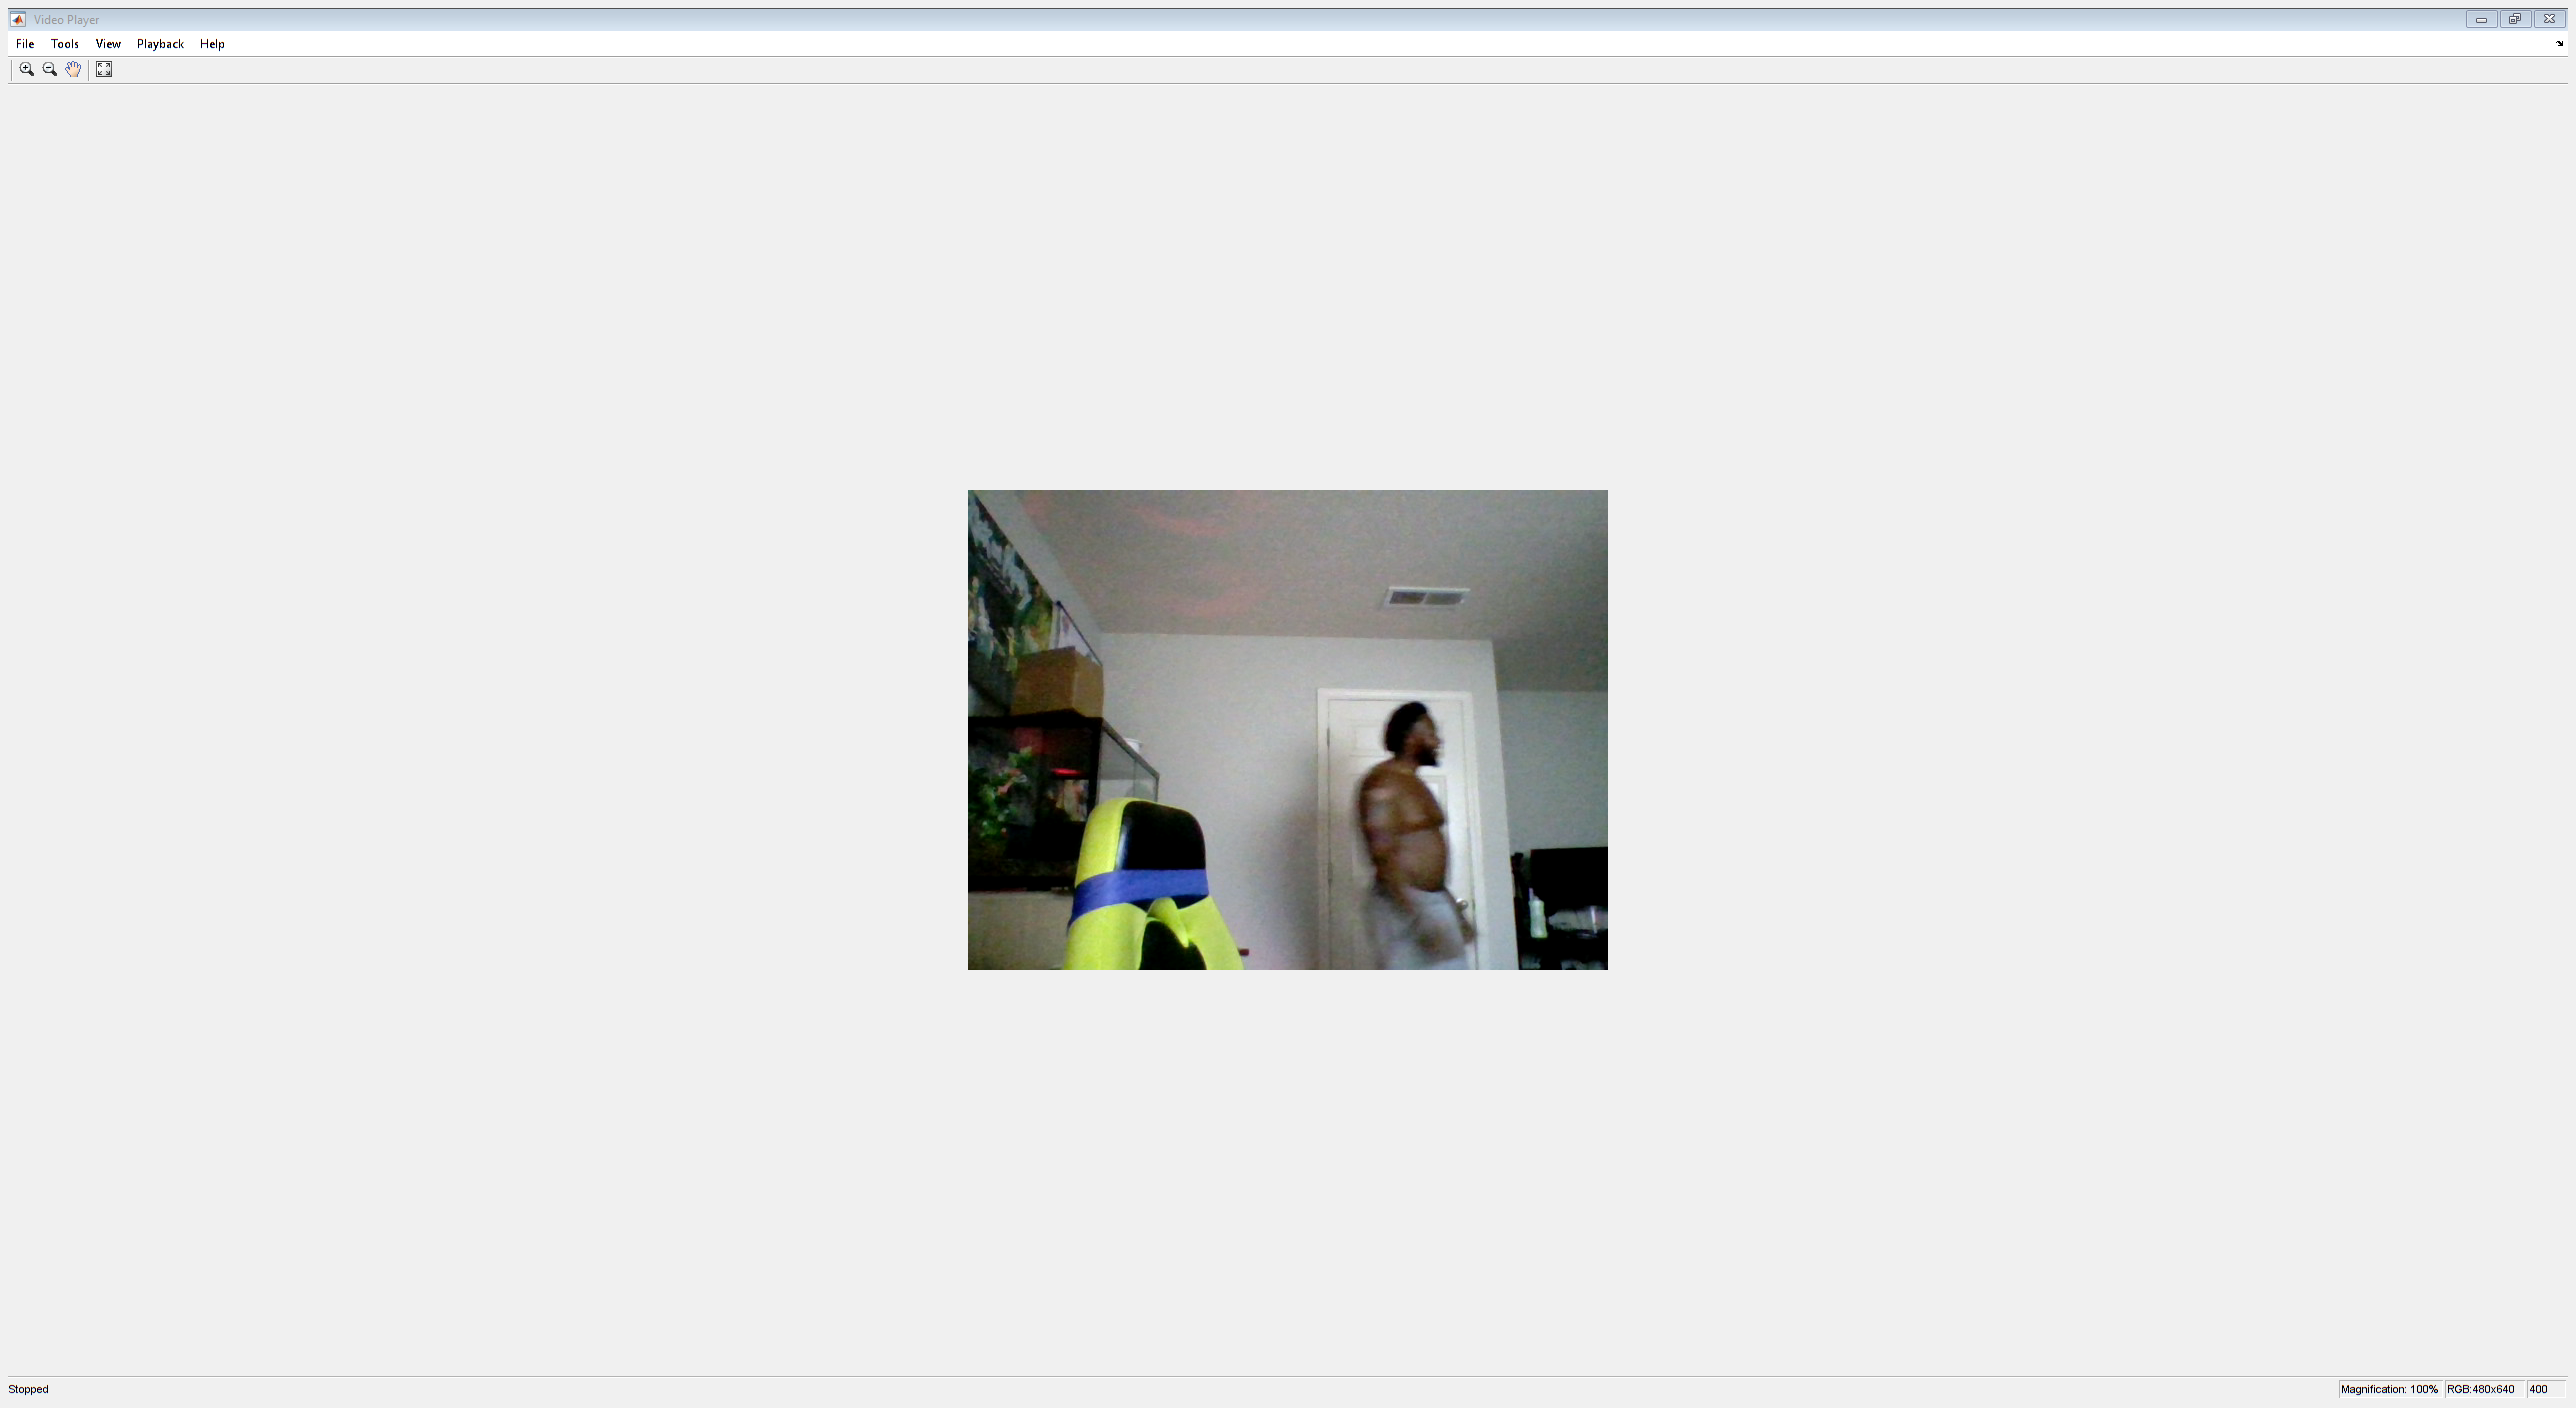


clear cam;
release(video_Player);

release(point_Tracker);
release(face_Detector);